# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

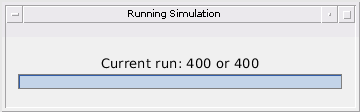

target_velocity = -1

estimated_ranges =   112.1050       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.2037       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.6994       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.8267       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   119.0000  118.9000  118.7999  118.6999  118.5998  118.4998  118.3997  118.2997  118.1996  118.0996


estimated_velocities =     3.0300       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0571       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0125       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =      3     3     3     3     3     3     3     3     3     3


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     6.8950
    6.6963
    6.1005
    5.8731
    5.0812
    5.3485
    4.5250
    3.8172
    4.3095
    3.7525


percent_error_velocities =     0.0300
    0.0571
    0.0013
    0.0125
    0.0154
    0.0037
    0.0406
    0.0366
    0.0281
    0.0067


target_velocity = -17

estimated_ranges =   108.9270       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.0884       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.6283       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.4081       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   113.0000  112.3664  111.7328  111.0991  110.4655  109.8319  109.1983  108.5646  107.9310  107.2974


estimated_velocities =    19.0485       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0058       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0380       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0301       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     19    19    19    19    19    19    19    19    19    19


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     4.0730
    2.2779
    1.1044
    0.3090
    1.4120
    3.5225
    4.1911
    5.8744
    4.0621
    2.6272


percent_error_velocities =     0.0485
    0.0058
    0.0380
    0.0301
    0.0292
    0.0410
    0.0555
    0.0537
    0.0390
    0.0323


target_velocity = 26

estimated_ranges =   143.7866       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.2679       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.1879       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.8560       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   142.0000  142.8004  143.6007  144.4011  145.2015  146.0018  146.8022  147.6026  148.4029  149.2033


estimated_velocities =   -24.0160       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.0018       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.0230       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.0108       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =    -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     2
     2
     2
     2
     1


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     1.7866
    0.4676
    2.4128
    3.5451
    6.2109
    4.1207
    2.5855
    1.1006
    0.5491
    4.4461


percent_error_velocities =     0.0160
    0.0018
    0.0230
    0.0108
    0.0377
    0.0234
    0.0180
    0.0037
    0.0111
    0.0915


target_velocity = -17

estimated_ranges =   144.0937       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.9374       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.7645       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.7923       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   140.0000  139.3664  138.7328  138.0991  137.4655  136.8319  136.1983  135.5646  134.9310  134.2974


estimated_velocities =    18.9613       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0575       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9476       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0454       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     19    19    19    19    19    19    19    19    19    19


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     4.0937
    7.4289
    4.9682
    3.3069
    2.4858
    1.3084
    0.3440
    2.3106
    5.2487
    8.1206


percent_error_velocities =     0.0387
    0.0575
    0.0524
    0.0454
    0.0070
    0.0197
    0.0298
    0.0134
    0.0146
    0.0372


target_velocity = 19

estimated_ranges =   114.5812       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.6868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.3866       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.6622       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   110.0000  110.5669  111.1339  111.7008  112.2677  112.8346  113.4016  113.9685  114.5354  115.1023


estimated_velocities =   -17.0267       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0301       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9998       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0153       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =    -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     4.5812
    3.1199
    2.2527
    0.9614
    0.2371
    1.2722
    2.8767
    5.6175
    6.6430
    5.1584


percent_error_velocities =     0.0267
    0.0301
    0.0002
    0.0153
    0.0130
    0.0494
    0.0761
    0.1177
    0.0010
    0.0640


target_velocity = -23

estimated_ranges =   136.5164       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.7547       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.9625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.9320       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   136.0000  135.1663  134.3326  133.4989  132.6651  131.8314  130.9977  130.1640  129.3303  128.4966


estimated_velocities =    24.9964       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0230       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0555       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.9916       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     25    25    25    25    25    25    25    25    25    25


detected =      1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5164
    2.5884
    8.3701
    5.5669
    3.4803
    1.9768
    0.9229
    3.8316
    9.3539
    5.7102


percent_error_velocities = 10×1
    0.0036
    0.0230
    0.0555
    0.0084
    0.0299
    0.0403
    0.0283
    0.0797
    0.0906
    0.0474


target_velocity = -18

estimated_ranges = 10×30
   37.6523       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.5270       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.1194       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9201       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   32.3330   31.6661   30.9991   30.3321   29.6651   28.9982   28.3312   27.6642   26.9973


estimated_velocities = 10×30
   19.9722       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9756       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9745       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    4.6523
    5.8060
    3.5467
    2.0790
    0.9243
    0.3459
    1.8813
    3.5117
    8.4668
    6.7279


percent_error_velocities = 10×1
    0.0278
    0.0235
    0.0244
    0.0255
    0.0242
    0.0261
    0.0232
    0.0259
    0.0194
    0.0321


target_velocity = 21

estimated_ranges = 10×30
   60.6355       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.4223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.8208       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.9703       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   62.0000   62.6336   63.2672   63.9009   64.5345   65.1681   65.8017   66.4354   67.0690   67.7026


estimated_velocities = 10×30
  -19.0251       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.0246       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.0197       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.0296       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.3645
    3.2113
    4.4464
    6.0694
    4.2770
    2.7454
    1.5550
    0.4281
    0.8901
    2.7017


percent_error_velocities = 10×1
    0.0251
    0.0246
    0.0197
    0.0296
    0.0319
    0.0231
    0.0294
    0.0264
    0.0208
    0.0436


target_velocity = -5

estimated_ranges = 10×30
   78.1912       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.7426       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.1900       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.7732       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   83.0000   82.7666   82.5331   82.2997   82.0662   81.8328   81.5994   81.3659   81.1325   80.8990


estimated_velocities = 10×30
    6.9667       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9656       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9716       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9735       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.8088
    4.0239
    3.3431
    2.5264
    1.7930
    1.3312
    0.8694
    0.4606
    0.0234
    0.2918


percent_error_velocities = 10×1
    0.0333
    0.0344
    0.0284
    0.0265
    0.0280
    0.0200
    0.0348
    0.0360
    0.0319
    0.0208


target_velocity = -11

estimated_ranges = 10×30
   54.4621       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.8329       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   55.4272       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.2950       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   56.0000   55.5665   55.1329   54.6994   54.2659   53.8323   53.3988   52.9653   52.5317   52.0982


estimated_velocities = 10×30
   12.9933       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9893       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9895       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9953       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.5379
    0.7335
    0.2943
    1.5956
    3.2425
    5.0864
    6.7921
    7.4542
    5.7726
    4.1981


percent_error_velocities = 10×1
    0.0067
    0.0107
    0.0105
    0.0047
    0.0095
    0.0123
    0.0175
    0.0174
    0.0124
    0.0088


target_velocity = 27

estimated_ranges = 10×30
  117.0982       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.3800       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.8833       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.6981       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  118.0000  118.8337  119.6674  120.5011  121.3349  122.1686  123.0023  123.8360  124.6697  125.5034


estimated_velocities = 10×30
  -25.0193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.0132       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.0022       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9998       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9018
    5.4538
    7.2159
    5.1969
    2.5235
    0.3396
    1.6537
    4.1940
    8.3973
    4.4415


percent_error_velocities = 10×1
    0.0193
    0.0132
    0.0022
    0.0002
    0.0098
    0.0005
    0.0233
    0.0049
    0.0176
    0.0409


target_velocity = 28

estimated_ranges = 10×30
   99.8053       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.3980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.7186       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.6269       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   95.0000   95.8671   96.7341   97.6012   98.4683   99.3353  100.2024  101.0694  101.9365  102.8036


estimated_velocities = 10×30
  -25.9739       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9879       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9774       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9540       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.8053
    2.5310
    0.9845
    0.9743
    3.3935
    7.2143
    4.5874
    2.8912
    1.1171
    1.4739


percent_error_velocities = 10×1
    0.0261
    0.0121
    0.0226
    0.0460
    0.0443
    0.0053
    0.0115
    0.0085
    0.0225
    0.0289


target_velocity = -27

estimated_ranges = 10×30
   43.8172       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   44.6126       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.9356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.0106       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   46.0000   45.0329   44.0658   43.0987   42.1316   41.1645   40.1973   39.2302   38.2631   37.2960


estimated_velocities = 10×30
   28.9978       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9971       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9994       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9968       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.1828
    0.4203
    1.8698
    7.0881
    5.3017
    3.1516
    1.4438
    0.9159
    5.6107
    6.6669


percent_error_velocities = 10×1
    0.0022
    0.0029
    0.0006
    0.0032
    0.0030
    0.0013
    0.0005
    0.0046
    0.0008
    0.0026


target_velocity = -22

estimated_ranges = 10×30
  105.0867       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.1618       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.4699       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.5370       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  114.0000  113.1996  112.3993  111.5989  110.7985  109.9982  109.1978  108.3974  107.5971  106.7967


estimated_velocities = 10×30
   23.9567       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0334       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0101       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0225       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    8.9133
    5.0378
    2.9294
    1.0619
    0.6393
    2.6768
   10.4430
    5.8967
    3.3778
    1.7650


percent_error_velocities = 10×1
    0.0433
    0.0334
    0.0101
    0.0225
    0.0310
    0.0136
    0.0000
    0.0136
    0.0169
    0.0141


target_velocity = -15

estimated_ranges = 10×30
  107.2707       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.5797       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.6795       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.4009       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  105.0000  104.4331  103.8661  103.2992  102.7323  102.1654  101.5984  101.0315  100.4646   99.8977


estimated_velocities = 10×30
   16.9931       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0245       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0610       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0405       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2707
    5.1466
    7.1867
    5.8983
    4.1559
    2.5912
    1.7089
    0.5361
    0.8680
    2.9670


percent_error_velocities = 10×1
    0.0069
    0.0245
    0.0610
    0.0405
    0.0452
    0.0283
    0.0095
    0.0227
    0.0044
    0.0167


target_velocity = 15

estimated_ranges = 10×30
   66.9672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.6802       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.2282       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   65.4297       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   66.0000   66.4335   66.8671   67.3006   67.7341   68.1677   68.6012   69.0347   69.4683   69.9018


estimated_velocities = 10×30
  -12.9919       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9899       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9882       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9919       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9672
    0.2467
    0.6389
    1.8708
    3.2559
    5.6941
    7.1084
    6.1357
    4.8737
    3.7618


percent_error_velocities = 10×1
    0.0081
    0.0101
    0.0118
    0.0081
    0.0034
    0.0145
    0.0003
    0.0071
    0.0138
    0.0068


target_velocity = -2

estimated_ranges = 10×30
   72.3323       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.5027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.9208       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.2515       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   70.0000   69.8666   69.7332   69.5998   69.4664   69.3330   69.1996   69.0662   68.9328   68.7995


estimated_velocities = 10×30
    3.9899       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9860       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9872       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.0111       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.3323
    2.6361
    3.1876
    3.6516
    4.1109
    4.5684
    5.0371
    5.4785
    5.8596
    6.3947


percent_error_velocities = 10×1
    0.0101
    0.0140
    0.0128
    0.0111
    0.0001
    0.0126
    0.0134
    0.0028
    0.0342
    0.0147


target_velocity = -6

estimated_ranges = 10×30
   40.3927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.8765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.4937       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.2524       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   40.0000   39.7332   39.4664   39.1996   38.9328   38.6661   38.3993   38.1325   37.8657   37.5989


estimated_velocities = 10×30
    8.0047       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0064       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0024       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0082       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3927
    1.1433
    2.0273
    3.0528
    4.0416
    5.0495
    6.1134
    7.0492
    7.7338
    6.6525


percent_error_velocities = 10×1
    0.0047
    0.0064
    0.0024
    0.0082
    0.0064
    0.0048
    0.0061
    0.0148
    0.0028
    0.0077


target_velocity = -28

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   21.0000   19.9995   18.9991   17.9986   16.9982   15.9977   14.9973   13.9968   12.9963   11.9959


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0260       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0278       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     0     1     1     0     0     0     0     0     0     0


col_detection = 10×1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
   13.7256
   14.7261
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
    0.0260
    0.0278
         0
         0
         0
         0
         0
         0
         0


target_velocity = -24

estimated_ranges = 10×30
   83.6232       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.3142       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.4629       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.1030       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   86.1329   85.2659   84.3988   83.5317   82.6647   81.7976   80.9306   80.0635   79.1964


estimated_velocities = 10×30
   25.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9858       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9759       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9850       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3768
    1.8187
    0.1971
    3.7042
    8.7901
    5.7006
    2.8596
    0.8178
    1.1686
    3.8510


percent_error_velocities = 10×1
    0.0227
    0.0142
    0.0241
    0.0150
    0.0502
    0.0406
    0.0118
    0.0193
    0.0079
    0.0515


target_velocity = 18

estimated_ranges = 10×30
   46.9844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.4655       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.0003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.4654       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   45.0000   45.5336   46.0672   46.6007   47.1343   47.6679   48.2015   48.7350   49.2686   49.8022


estimated_velocities = 10×30
  -16.0107       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0106       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0088       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9844
    0.9319
    0.0669
    1.1353
    2.4385
    3.9601
    8.9523
    5.7079
    4.2575
    2.9660


percent_error_velocities = 10×1
    0.0107
    0.0085
    0.0106
    0.0088
    0.0125
    0.0179
    0.0167
    0.0096
    0.0104
    0.0100


target_velocity = 35

estimated_ranges = 10×30
   39.2724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.9111       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.1110       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.3947       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   34.0000   35.1005   36.2010   37.3015   38.4020   39.5025   40.6030   41.7035   42.8040   43.9045


estimated_velocities = 10×30
  -32.9977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9923       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9941       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9882       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.2724
    2.8106
    0.9100
    1.9068
    7.6885
    4.7772
    2.5120
    0.0671
         0
         0


percent_error_velocities = 10×1
    0.0023
    0.0077
    0.0059
    0.0118
    0.0044
    0.0081
    0.0102
    0.0054
         0
         0


target_velocity = 16

estimated_ranges = 10×30
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   20.0000   20.4669   20.9338   21.4006   21.8675   22.3344   22.8013   23.2682   23.7350   24.2019


estimated_velocities = 10×30
  -14.0315       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0338       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0301       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0284       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
   13.7252
   13.2583
   12.7914
   12.3245
   11.1536
   11.3908
    7.3326
    6.7875
    5.2692
    3.8957


percent_error_velocities = 10×1
    0.0315
    0.0338
    0.0301
    0.0284
    0.0069
    0.0276
    0.0290
    0.0322
    0.0312
    0.0330


target_velocity = -24

estimated_ranges = 10×30
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   22.0000   21.1329   20.2659   19.3988   18.5317   17.6647   16.7976   15.9306   15.0635   14.1964


estimated_velocities = 10×30
   25.9826       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9797       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     0     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
   11.7252
         0
   13.4593
   14.3264
   15.1934
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0174
         0
    0.0202
    0.0203
    0.0178
         0
         0
         0
         0
         0


target_velocity = 24

estimated_ranges = 10×30
   36.7167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8658       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.0927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.7638       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   36.7337   37.4673   38.2010   38.9347   39.6683   40.4020   41.1357   41.8694   42.6030


estimated_velocities = 10×30
  -22.0295       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0281       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0179       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7167
    0.8679
    3.3746
    7.5628
    5.7289
    3.7984
    2.1976
    0.5598
    1.7578
         0


percent_error_velocities = 10×1
    0.0295
    0.0281
    0.0356
    0.0179
    0.0272
    0.0317
    0.0283
    0.0284
    0.0257
         0


target_velocity = -33

estimated_ranges = 10×30
   52.2423       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.2119       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.6536       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.8672       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   57.0000   55.8328   54.6656   53.4984   52.3312   51.1640   49.9968   48.8296   47.6624   46.4952


estimated_velocities = 10×30
   35.0353       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0340       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0276       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.9910       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.7577
    2.6209
    0.0120
    5.3688
    6.4584
    3.3420
    0.5221
    3.3293
    8.0352
    3.5174


percent_error_velocities = 10×1
    0.0353
    0.0340
    0.0276
    0.0090
    0.0372
    0.0421
    0.0301
    0.0299
    0.0242
    0.0281


target_velocity = 33

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   13.0000   14.0338   15.0676   16.1014   17.1352   18.1690   19.2028   20.2366   21.2705   22.3043


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9680       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     0     1     0     0     1     1     1     1     1     1


col_detection = 10×1
     0
     1
     0
     0
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
   19.6914
         0
         0
   11.3893
    8.0617
    7.0279
   13.4885
   12.4547
   10.6513


percent_error_velocities = 10×1
         0
    0.0320
         0
         0
    0.0338
    0.0304
    0.0295
    0.0301
    0.0321
    0.0453


target_velocity = -31

estimated_ranges = 10×30
  300.1732  128.5240       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.3562       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.1579       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.8044       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  133.0000  131.8995  130.7990  129.6985  128.5980  127.4975  126.3970  125.2965  124.1960  123.0955


estimated_velocities = 10×30
    8.6732   32.9969       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.0752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.0025       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.4760
    2.5433
    0.3589
    5.1059
    7.3886
    2.7614
    0.8086
    1.7897
    4.1249
    4.7605


percent_error_velocities = 10×1
    0.0031
    0.0246
    0.0752
    0.0025
    0.0262
    0.0208
    0.0076
    0.0044
    0.1229
    0.0446


target_velocity = -7

estimated_ranges = 10×30
  104.3041       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.9565       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.2511       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.4224       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  107.6999  107.3997  107.0996  106.7995  106.4993  106.1992  105.8990  105.5989  105.2988


estimated_velocities = 10×30
    9.0184       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0226       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0087       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0004       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.6959
    2.7433
    2.1487
    1.6772
    1.3193
    0.8993
    0.3083
    0.2778
    1.0592
    2.2423


percent_error_velocities = 10×1
    0.0184
    0.0226
    0.0087
    0.0004
    0.0220
    0.0209
    0.0349
    0.0364
    0.0108
    0.0216


target_velocity = 31

estimated_ranges = 10×30
   42.9511       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.1522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.8672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.1465       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   33.9671   34.9342   35.9013   36.8684   37.8355   38.8027   39.7698   40.7369   41.7040


estimated_velocities = 10×30
  -29.0008       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9994       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0003       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    9.9511
    5.1851
    2.9330
    1.2452
    0.8780
    5.1805
    6.4052
    3.9394
    2.0352
    0.5247


percent_error_velocities = 10×1
    0.0008
    0.0002
    0.0006
    0.0003
    0.0011
    0.0024
    0.0014
    0.0006
    0.0001
    0.0006


target_velocity = 12

estimated_ranges = 10×30
  126.3899       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.1129       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.1565       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.0422       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  128.0000  128.3335  128.6670  129.0005  129.3339  129.6674  130.0009  130.3344  130.6679  131.0014


estimated_velocities = 10×30
   -9.9900       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9590       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9883       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.0110       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6101
    2.2206
    3.5105
    3.9582
    6.3017
    6.2481
    5.6364
    4.7353
    3.6739
    2.8494


percent_error_velocities = 10×1
    0.0100
    0.0410
    0.0117
    0.0110
    0.0962
    0.0072
    0.0086
    0.0030
    0.0286
    0.0525


target_velocity = -11

estimated_ranges = 10×30
  140.7876       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.1277       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.1699       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.9518       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  143.0000  142.5665  142.1329  141.6994  141.2659  140.8323  140.3988  139.9653  139.5317  139.0982


estimated_velocities = 10×30
   13.0091       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9935       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0091       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2124
    1.4388
    0.9630
    0.2524
    1.4432
    1.9472
    3.2460
    4.0356
         0
    5.4624


percent_error_velocities = 10×1
    0.0091
    0.0065
    0.0356
    0.0091
    0.0388
    0.0237
    0.0036
    0.0186
         0
    0.0669


target_velocity = -23

estimated_ranges = 10×30
   61.8484       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.1333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.2073       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.2734       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   59.0000   58.1663   57.3326   56.4989   55.6651   54.8314   53.9977   53.1640   52.3303   51.4966


estimated_velocities = 10×30
   25.0046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0137       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0059       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0118       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.8484
    7.0330
    5.1252
    3.2255
    1.6912
    0.1499
    3.3701
    8.7612
    5.9487
    3.3379


percent_error_velocities = 10×1
    0.0046
    0.0137
    0.0059
    0.0118
    0.0001
    0.0068
    0.0072
    0.0115
    0.0135
    0.0083


target_velocity = -17

estimated_ranges = 10×30
  103.6720       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.9106       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.1262       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  226.3364  105.3502       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  107.3664  106.7328  106.0991  105.4655  104.8319  104.1983  103.5646  102.9310  102.2974


estimated_velocities = 10×30
   19.0389       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0350       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.4264   19.0224       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.3280
    2.4558
    1.6065
    0.7489
    0.9652
    2.8775
    6.7483
    6.8087
    4.6729
    3.5629


percent_error_velocities = 10×1
    0.0389
    0.0350
    0.0195
    0.0224
    0.0134
    0.0323
    0.0930
    0.0383
    0.0252
    0.0561


target_velocity = 23

estimated_ranges = 10×30
   81.9290       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.9160       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.4797       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.1850       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   82.7003   83.4006   84.1010   84.8013   85.5016   86.2019   86.9022   87.6026   88.3029


estimated_velocities = 10×30
  -20.9889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.9875       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.0289       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.0057       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0710
    1.7843
    3.9209
    7.0841
    5.0529
    3.4183
    1.9516
    0.3361
    1.8921
    4.7044


percent_error_velocities = 10×1
    0.0111
    0.0125
    0.0289
    0.0057
    0.0038
    0.0009
    0.0038
    0.0065
    0.0001
    0.0020


target_velocity = -10

estimated_ranges = 10×30
   72.9824       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.4959       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.1575       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.6997       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   77.5998   77.1996   76.7995   76.3993   75.9991   75.5989   75.1987   74.7985   74.3984


estimated_velocities = 10×30
   11.9932       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9924       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9779       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9837       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.0176
    4.1039
    3.0421
    2.0997
    1.3515
    0.6782
    0.0443
    0.7641
    1.7933
    3.1926


percent_error_velocities = 10×1
    0.0068
    0.0076
    0.0221
    0.0163
    0.0139
    0.0177
    0.0182
    0.0107
    0.0273
    0.0037


target_velocity = -6

estimated_ranges = 10×30
  362.3162   61.0708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.4742       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.8494       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.5501       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   60.0000   59.7332   59.4664   59.1996   58.9328   58.6661   58.3993   58.1325   57.8657   57.5989


estimated_velocities = 10×30
   -3.6290    8.0049       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0089       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0108       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0053       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0708
    1.7410
    2.3830
    3.3505
    4.1263
    6.2070
    6.2031
    6.6262
    5.9679
    5.1440


percent_error_velocities = 10×1
    0.0049
    0.0089
    0.0108
    0.0053
    0.0059
    0.0074
    0.0223
    0.0034
    0.0013
    0.0027


target_velocity = 21

estimated_ranges = 10×30
  102.8860       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.5560       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.6926       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.2034       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  102.6336  103.2672  103.9009  104.5345  105.1681  105.8017  106.4354  107.0690  107.7026


estimated_velocities = 10×30
  -19.0233       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.0347       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.0184       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.0575       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8860
    1.0777
    3.5746
    6.6974
    7.3315
    4.8674
    2.5892
    1.2190
    0.3085
    1.5654


percent_error_velocities = 10×1
    0.0233
    0.0347
    0.0184
    0.0575
    0.0747
    0.0421
    0.0316
    0.0190
    0.0227
    0.0185


target_velocity = 15

estimated_ranges = 10×30
  127.4898       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.2968       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.6155       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.7550       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  127.4335  127.8671  128.3006  128.7341  129.1677  129.6012  130.0347  130.4683  130.9018


estimated_velocities = 10×30
  -12.9735       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9938       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.0163       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.4898
    0.1368
    1.2516
    2.5456
    2.5385
    5.5538
    6.4170
    5.6024
    4.3854
    3.2508


percent_error_velocities = 10×1
    0.0265
    0.0043
    0.0062
    0.0163
    0.0028
    0.0776
    0.0986
    0.0025
    0.0026
    0.0137


target_velocity = -33

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.1434       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    6.0000    4.8328    3.6656    2.4984    1.3312    0.1640    1.0032    2.1704    3.3376    4.5048


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.3850       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -32

estimated_ranges = 10×30
   79.2787       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  165.7814   81.1833       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.0819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.2201       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   81.0000   79.8661   78.7323   77.5984   76.4646   75.3307   74.1969   73.0630   71.9292   70.7953


estimated_velocities = 10×30
   33.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.1668   33.9825       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.0280       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.9767       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.7213
    1.3171
    4.3496
    5.3784
    2.4976
    0.4627
    2.4981
    7.1129
    4.1480
    2.0720


percent_error_velocities = 10×1
    0.0227
    0.0175
    0.0280
    0.0233
    0.0187
    0.0192
    0.0034
    0.0015
    0.0168
    0.0063


target_velocity = 30

estimated_ranges = 10×30
  135.1274       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.5231       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.2114       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.7182       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  131.0000  131.9338  132.8675  133.8013  134.7350  135.6688  136.6026  137.5363  138.4701  139.4038


estimated_velocities = 10×30
  -27.9989       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9894       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9341       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.0141       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.1274
    2.5893
    0.3439
    3.0831
    7.4289
    5.0076
    2.4537
    0.8006
    1.9577
         0


percent_error_velocities = 10×1
    0.0011
    0.0106
    0.0659
    0.0141
    0.0422
    0.0662
    0.0160
    0.0412
    0.0300
         0


target_velocity = -8

estimated_ranges = 10×30
   72.9879       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.6350       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.2829       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.7039       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   77.6665   77.3330   76.9995   76.6661   76.3326   75.9991   75.6656   75.3321   74.9986


estimated_velocities = 10×30
    9.9496       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9753       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9720       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9689       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.0121
    4.0315
    3.0501
    2.2957
    1.7753
    1.1709
    0.5340
    0.0380
    0.7339
    1.3986


percent_error_velocities = 10×1
    0.0504
    0.0247
    0.0280
    0.0311
    0.0257
    0.0344
    0.0263
    0.0258
    0.0268
    0.0242


target_velocity = 12

estimated_ranges = 10×30
   70.4808       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.7900       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.8403       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.0414       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   72.0000   72.3335   72.6670   73.0005   73.3339   73.6674   74.0009   74.3344   74.6679   75.0014


estimated_velocities = 10×30
   -9.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9713       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9760       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.5192
    2.5435
    3.8267
    4.9590
    6.2773
         0
         0
    5.5342
    3.9151
    2.6944


percent_error_velocities = 10×1
    0.0282
    0.0287
    0.0263
    0.0240
    0.0157
         0
         0
    0.0271
    0.0167
    0.0318


target_velocity = 25

estimated_ranges = 10×30
   82.0115       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.9009       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.5177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.9949       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   82.7670   83.5340   84.3011   85.0681   85.8351   86.6021   87.3691   88.1361   88.9032


estimated_velocities = 10×30
  -22.9622       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9742       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9859       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9841       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0115
    1.8661
    6.0163
    6.6939
    4.1931
    2.7522
    1.0755
    1.0286
    3.6953
    8.9825


percent_error_velocities = 10×1
    0.0378
    0.0258
    0.0141
    0.0159
    0.0324
    0.0340
    0.0210
    0.0366
    0.0371
    0.0284


target_velocity = -10

estimated_ranges = 10×30
  100.1841       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.4958       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.9006       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.5347       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  101.5998  101.1996  100.7995  100.3993   99.9991   99.5989   99.1987   98.7985   98.3984


estimated_velocities = 10×30
   11.9668       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9638       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9776       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9771       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.8159
    1.1040
    0.2990
    0.7352
    1.8860
    2.9728
    4.5361
    6.3374
    8.4919
    6.4558


percent_error_velocities = 10×1
    0.0332
    0.0362
    0.0224
    0.0229
    0.0123
    0.0193
    0.0409
    0.0378
    0.0661
    0.0812


target_velocity = 9

estimated_ranges = 10×30
   48.3090       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.7310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.1836       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.7967       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   44.0000   44.2334   44.4669   44.7003   44.9338   45.1672   45.4006   45.6341   45.8675   46.1010


estimated_velocities = 10×30
   -6.9662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9715       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9652       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.3090
    3.4975
    2.7167
    2.0964
    1.5761
    1.1034
    0.6661
    0.2933
    0.1126
    0.5412


percent_error_velocities = 10×1
    0.0338
    0.0285
    0.0312
    0.0348
    0.0314
    0.0306
    0.0297
    0.0309
    0.0306
    0.0306


target_velocity = -27

estimated_ranges = 10×30
   37.0355       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.1176       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.8951       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.4897       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   42.0000   41.0329   40.0658   39.0987   38.1316   37.1645   36.1973   35.2302   34.2631   33.2960


estimated_velocities = 10×30
   29.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.0010       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.0016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.0039       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    4.9645
    2.9153
    1.1707
    1.3910
    6.2526
    6.2232
    3.5295
    1.2633
    1.4327
    4.5686


percent_error_velocities = 10×1
    0.0001
    0.0010
    0.0016
    0.0039
    0.0086
    0.0019
    0.0002
    0.0002
    0.0021
    0.0006


target_velocity = 30

estimated_ranges = 10×30
  105.7465       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.2118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.0134       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  103.3777       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   99.9338  100.8675  101.8013  102.7350  103.6688  104.6026  105.5363  106.4701  107.4038


estimated_velocities = 10×30
  -27.9331       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9530       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9736       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9347       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.7465
    5.2781
    3.1459
    1.5764
    0.3269
    4.7759
    7.2406
    4.3541
    1.9531
    0.3984


percent_error_velocities = 10×1
    0.0669
    0.0470
    0.0264
    0.0653
    0.0213
    0.0502
    0.0122
    0.0280
    0.0112
    0.0712


target_velocity = 20

estimated_ranges = 10×30
  122.5932       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.2159       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.5220       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.2643       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  122.0000  122.6003  123.2005  123.8008  124.4011  125.0014  125.6016  126.2019  126.8022  127.4025


estimated_velocities = 10×30
  -17.9742       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9955       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9472       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -18.0501       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5932
    1.3844
    2.6785
    4.5365
    9.1988
    5.3266
    3.3031
    2.2541
    0.8612
    0.1238


percent_error_velocities = 10×1
    0.0258
    0.0045
    0.0528
    0.0501
    0.0445
    0.0306
    0.0391
    0.0247
    0.0226
    0.0424


target_velocity = -17

estimated_ranges = 10×30
  116.1525       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.9093       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  116.3664  115.7328  115.0991  114.4655  113.8319  113.1983  112.5646  111.9310  111.2974


estimated_velocities = 10×30
   18.9533       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0260       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     0     0     0     0     0     0     1     0


col_detection = 10×1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8475
    0.5429
         0
         0
         0
         0
         0
         0
    1.0336
         0


percent_error_velocities = 10×1
    0.0467
    0.0260
         0
         0
         0
         0
         0
         0
    0.0455
         0


target_velocity = -13

estimated_ranges = 10×30
  123.4306       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.4635       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.1274       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.0674       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  120.0000  119.4998  118.9995  118.4993  117.9991  117.4989  116.9986  116.4984  115.9982  115.4979


estimated_velocities = 10×30
   14.9470       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.0412       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9702       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9408       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.4306
    6.9638
    6.8722
    6.4319
    4.0213
    2.7740
    1.8628
    0.2374
    0.9366
    2.2333


percent_error_velocities = 10×1
    0.0530
    0.0412
    0.0298
    0.0592
    0.0464
    0.0399
    0.0376
    0.0444
    0.0139
    0.0232


target_velocity = 22

estimated_ranges = 10×30
  103.3818       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.0897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.6979       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.9011       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   94.0000   94.6670   95.3339   96.0009   96.6679   97.3349   98.0018   98.6688   99.3358  100.0027


estimated_velocities = 10×30
  -19.9366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9237       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.0389       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9639       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    9.3818
    4.4228
    3.3639
    1.9002
    0.8409
    0.3011
    2.6324
    4.1331
    7.3012
    5.1582


percent_error_velocities = 10×1
    0.0634
    0.0763
    0.0389
    0.0361
    0.0058
    0.0461
    0.0197
    0.0635
    0.0778
    0.0505


target_velocity = -5

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
    9.0000    8.7666    8.5331    8.2997    8.0662    7.8328    7.5994    7.3659    7.1325    6.8990


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 32

estimated_ranges = 10×30
   88.7747       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   87.8919       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.7443       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.9203       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   86.0000   87.0005   88.0009   89.0014   90.0018   91.0023   92.0027   93.0032   94.0037   95.0041


estimated_velocities = 10×30
  -30.0323       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0353       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0441       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0252       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.7747
    0.8914
    2.2566
    8.9189
    5.4874
    2.6958
    0.2442
    2.4378
    9.7653
    5.0176


percent_error_velocities = 10×1
    0.0323
    0.0353
    0.0441
    0.0252
    0.0135
    0.0260
    0.0301
    0.0355
    0.0227
    0.0179


target_velocity = 33

estimated_ranges = 10×30
  121.8729       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.2362       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.2515       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.0461       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  123.0000  124.0338  125.0676  126.1014  127.1352  128.1690  129.2028  130.2366  131.2705  132.3043


estimated_velocities = 10×30
  -30.9674       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9083       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9679       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1271
    4.7976
    6.1839
    2.9447
    0.8614
    1.1660
   11.0716
    5.4948
    3.4471
    1.8581


percent_error_velocities = 10×1
    0.0326
    0.0917
    0.0201
    0.0321
    0.0420
    0.0081
    0.1552
    0.0302
    0.0049
    0.0030


target_velocity = 24

estimated_ranges = 10×30
   65.8329       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.5859       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.3273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.5724       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   59.0000   59.7337   60.4673   61.2010   61.9347   62.6683   63.4020   64.1357   64.8694   65.6030


estimated_velocities = 10×30
  -22.0261       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0297       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0365       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0388       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.8329
    3.8522
    1.8600
    0.3714
    0.9893
    3.1477
    9.9689
    5.5980
    3.4311
    2.1044


percent_error_velocities = 10×1
    0.0261
    0.0297
    0.0365
    0.0388
    0.0257
    0.0202
    0.0429
    0.0410
    0.0374
    0.0260


target_velocity = 33

estimated_ranges = 10×30
   88.0081       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.1496       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.5003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.5438       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   88.0338   89.0676   90.1014   91.1352   92.1690   93.2028   94.2366   95.2705   96.3043


estimated_velocities = 10×30
  -30.9605       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9846       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9788       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9551       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     0
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.0081
    2.8842
    8.4327
    5.4424
    2.5870
    0.1547
    3.0880
         0
    3.9968
    1.8667


percent_error_velocities = 10×1
    0.0395
    0.0154
    0.0212
    0.0449
    0.0354
    0.0273
    0.0497
         0
    0.0274
    0.0263


target_velocity = 18

estimated_ranges = 10×30
   78.2474       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.3180       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.8943       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.2935       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   75.0000   75.5336   76.0672   76.6007   77.1343   77.6679   78.2015   78.7350   79.2686   79.8022


estimated_velocities = 10×30
  -16.0146       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0134       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0120       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.2474
    1.7844
    0.8272
    0.3072
    1.3315
    2.7711
    4.4993
    8.9731
    5.6304
    3.8546


percent_error_velocities = 10×1
    0.0146
    0.0118
    0.0134
    0.0120
    0.0158
    0.0106
    0.0091
    0.0187
    0.0260
    0.0163


target_velocity = -5

estimated_ranges = 10×30
  135.2134       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.4208       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.1080       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.8830       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  138.0000  137.7666  137.5331  137.2997  137.0662  136.8328  136.5994  136.3659  136.1325  135.8990


estimated_velocities = 10×30
    6.9743       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9641       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9630       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.7866
    2.3458
    1.4251
    1.4167
    0.6227
    0.5723
    0.0394
    0.3291
    0.4201
    1.1682


percent_error_velocities = 10×1
    0.0257
    0.0292
    0.0359
    0.0370
    0.0318
    0.0137
    0.0104
    0.0032
    0.0492
    0.0505


target_velocity = 24

estimated_ranges = 10×30
   68.3027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.5390       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.0424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.1828       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   65.0000   65.7337   66.4673   67.2010   67.9347   68.6683   69.4020   70.1357   70.8694   71.6030


estimated_velocities = 10×30
  -22.0322       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0246       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0249       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3027
    1.8053
    0.5751
    1.0182
    3.1654
         0
    5.5530
    3.7076
    2.1952
    0.5575


percent_error_velocities = 10×1
    0.0322
    0.0246
    0.0310
    0.0249
    0.0311
         0
    0.0218
    0.0310
    0.0362
    0.0321


target_velocity = 34

estimated_ranges = 10×30
   52.5660       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.3996       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.8420       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.2410       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   51.0000   52.0672   53.1343   54.2015   55.2686   56.3358   57.4029   58.4701   59.5372   60.6044


estimated_velocities = 10×30
  -32.0217       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0215       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0234       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0215       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     0
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.5660
    0.6675
    5.2923
    6.0395
    3.5050
    1.4403
    1.9964
         0
    5.5331
    2.4617


percent_error_velocities = 10×1
    0.0217
    0.0215
    0.0234
    0.0215
    0.0204
    0.0183
    0.0189
         0
    0.0149
    0.0157


target_velocity = -22

estimated_ranges = 10×30
   91.2608       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.3376       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.2276       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.8022       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   90.0000   89.1996   88.3993   87.5989   86.7985   85.9982   85.1978   84.3974   83.5971   82.7967


estimated_velocities = 10×30
   24.0132       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0429       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0260       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0174       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.2608
    4.1379
    7.1717
    4.7967
    2.9452
    1.3326
    0.5748
    3.7169
    9.0635
    5.8445


percent_error_velocities = 10×1
    0.0132
    0.0429
    0.0260
    0.0174
    0.0130
    0.0089
    0.0367
    0.0099
    0.0287
    0.0169


target_velocity = -3

estimated_ranges = 10×30
   68.7280       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.9087       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.7468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.5209       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   64.0000   63.8333   63.6665   63.4998   63.3330   63.1663   62.9995   62.8328   62.6661   62.4993


estimated_velocities = 10×30
    4.9894       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.0019       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.0018       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9973       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.7280
    5.0754
    5.0803
    5.0212
    7.5427
    5.5768
    5.2702
    4.9017
    4.3784
    3.8200


percent_error_velocities = 10×1
    0.0106
    0.0019
    0.0018
    0.0027
    0.0110
    0.0264
    0.0280
    0.0015
    0.0111
    0.0172


target_velocity = -15

estimated_ranges = 10×30
   81.9438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.9328       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.4591       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.0382       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   80.0000   79.4331   78.8661   78.2992   77.7323   77.1654   76.5984   76.0315   75.4646   74.8977


estimated_velocities = 10×30
   17.0110       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0066       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0069       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9741       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9438
    3.4997
    4.5929
    6.2610
    4.6655
    2.9884
    1.8279
    0.9820
    0.0211
    1.4036


percent_error_velocities = 10×1
    0.0110
    0.0066
    0.0069
    0.0259
    0.0054
    0.0118
    0.0279
    0.0142
    0.0055
    0.0036


target_velocity = 32

estimated_ranges = 10×30
   37.3912       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.3930       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.1495       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.9136       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   43.0000   44.0005   45.0009   46.0014   47.0018   48.0023   49.0027   50.0032   51.0037   52.0041


estimated_velocities = 10×30
  -30.0265       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0237       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0259       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0261       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.6088
    6.3925
    3.1486
    0.9122
    1.3910
    3.9880
    5.7723
    3.2063
    1.4881
    0.7055


percent_error_velocities = 10×1
    0.0265
    0.0237
    0.0259
    0.0261
    0.0252
    0.0256
    0.0273
    0.0339
    0.0335
    0.0291


target_velocity = 3

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   11.0000   11.0333   11.0667   11.1000   11.1334   11.1667   11.2001   11.2334   11.2668   11.3001


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 26

estimated_ranges = 10×30
  128.9273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.2584       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.8601       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.8521       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  126.8004  127.6007  128.4011  129.2015  130.0018  130.8022  131.6026  132.4029  133.2033


estimated_velocities = 10×30
  -24.0003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.0201       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.0266       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.0244       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     0     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     0
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.9273
    1.4580
    0.2594
    1.5490
         0
    5.6609
    4.2402
    2.4899
    1.1179
    0.4574


percent_error_velocities = 10×1
    0.0003
    0.0201
    0.0266
    0.0244
         0
    0.0118
    0.0056
    0.0221
    0.0312
    0.0038


target_velocity = 18

estimated_ranges = 10×30
   60.5191       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.6432       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.6117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.1272       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   62.0000   62.5336   63.0672   63.6007   64.1343   64.6679   65.2015   65.7350   66.2686   66.8022


estimated_velocities = 10×30
  -16.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0116       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0053       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.0051       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.4809
    2.8903
    4.4554
    7.5265
    5.4009
    3.6089
    2.6269
    1.5286
    0.6438
    0.4297


percent_error_velocities = 10×1
    0.0001
    0.0116
    0.0053
    0.0051
    0.0098
    0.0131
    0.0126
    0.0102
    0.0133
    0.0111


target_velocity = -21

estimated_ranges = 10×30
  141.5020       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.4771       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.9780       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.1112       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  140.2330  139.4660  138.6989  137.9319  137.1649  136.3979  135.6309  134.8639  134.0968


estimated_velocities = 10×30
   22.9611       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.0226       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9242       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9625       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5020
    3.2441
    6.4880
    5.5877
    3.3747
    1.8025
    0.5828
    1.4662
    5.0304
    7.5312


percent_error_velocities = 10×1
    0.0389
    0.0226
    0.0758
    0.0375
    0.0228
    0.0089
    0.0282
    0.0460
    0.0301
    0.0901


target_velocity = 2

estimated_ranges = 10×30
   39.8470       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.8743       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.9064       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.8522       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    41    41    41    41    41    41    41    41    41    41


estimated_velocities = 10×30
   -0.3085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.3085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.3085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3085       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1530
    1.1257
    1.0936
    1.1478
    1.1428
    1.0729
    1.0988
    1.1541
    1.1397
    1.1052


percent_error_velocities = 10×1
    0.3085
    0.3085
    0.3085
    0.3085
    0.3085
    0.3085
    0.3085
    0.3085
    0.3085
    0.3085


target_velocity = 22

estimated_ranges = 10×30
  144.3801       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.4299       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.1620       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  142.4946       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  141.6670  142.3339  143.0009  143.6679  144.3349  145.0018  145.6688  146.3358  147.0027


estimated_velocities = 10×30
  -19.9837       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9902       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9417       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9574       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     0     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3801
    1.7629
    0.8281
    0.5064
    2.2556
         0
    6.0787
    4.8838
    3.8034
    2.2041


percent_error_velocities = 10×1
    0.0163
    0.0098
    0.0583
    0.0426
    0.0770
         0
    0.0281
    0.0225
    0.0337
    0.0108


target_velocity = -12

estimated_ranges = 10×30
   36.5400       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7429       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.6051       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.2787       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   43.0000   42.5331   42.0662   41.5994   41.1325   40.6656   40.1987   39.7318   39.2650   38.7981


estimated_velocities = 10×30
   14.0271       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0307       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0318       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0320       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     1


percent_error_ranges = 10×1
    6.4600
    5.7902
    4.4611
    3.3206
    2.3212
    1.4191
    0.5191
    0.5766
    2.2355
    4.2110


percent_error_velocities = 10×1
    0.0271
    0.0307
    0.0318
    0.0320
    0.0326
    0.0328
    0.0302
    0.0316
    0.0284
    0.0310


target_velocity = -11

estimated_ranges = 10×30
  126.9910       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.9388       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.7019       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.1983       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  125.5665  125.1329  124.6994  124.2659  123.8323  123.3988  122.9653  122.5317  122.0982


estimated_velocities = 10×30
   12.9827       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0405       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9255       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     0     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9910
    2.3724
    3.5690
    4.4988
         0
    5.9551
    4.2593
    3.3822
    2.2520
    1.8943


percent_error_velocities = 10×1
    0.0173
    0.0263
    0.0405
    0.0745
         0
    0.0209
    0.0551
    0.0052
    0.0241
    0.0248


target_velocity = -6

estimated_ranges = 10×30
   95.8568       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.9017       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.0479       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.2476       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   97.0000   96.7332   96.4664   96.1996   95.9328   95.6661   95.3993   95.1325   94.8657   94.5989


estimated_velocities = 10×30
    8.0052       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9912       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0145       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0231       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1432
    0.8315
    0.4185
    0.0479
    0.6883
    1.2330
    1.9112
    2.5526
    3.1347
    3.9951


percent_error_velocities = 10×1
    0.0052
    0.0088
    0.0145
    0.0231
    0.0133
    0.0219
    0.0006
    0.0253
    0.0077
    0.0178


target_velocity = -14

estimated_ranges = 10×30
  142.2371       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.3691       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.9956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.4652       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  140.4664  139.9328  139.3993  138.8657  138.3321  137.7985  137.2650  136.7314  136.1978


estimated_velocities = 10×30
   16.0349       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9922       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.0411       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.0233       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.2371
    2.9027
    4.0627
    5.9340
    5.2944
    3.8683
    2.6904
    1.7613
    0.9085
    0.3706


percent_error_velocities = 10×1
    0.0349
    0.0078
    0.0411
    0.0233
    0.0388
    0.0309
    0.0394
    0.0239
    0.0040
    0.0371


target_velocity = 31

estimated_ranges = 10×30
   93.4815       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   92.2860       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.5740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.5871       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   91.0000   91.9671   92.9342   93.9013   94.8684   95.8355   96.8027   97.7698   98.7369   99.7040


estimated_velocities = 10×30
  -29.0068       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9902       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0052       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9938       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.4815
    0.3189
    2.3602
    4.3143
    5.2206
    2.8494
    0.9753
    0.9362
    3.1076
    6.2656


percent_error_velocities = 10×1
    0.0068
    0.0098
    0.0052
    0.0062
    0.0014
    0.0009
    0.0107
    0.0086
    0.0349
    0.0117


target_velocity = 32

estimated_ranges = 10×30
   30.8662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.3366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.0648       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9647       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   23.0000   24.0005   25.0009   26.0014   27.0018   28.0023   29.0027   30.0032   31.0037   32.0041


estimated_velocities = 10×30
  -30.0259       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0280       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0282       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0285       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    7.8662
    5.3361
    3.0639
    0.9633
    0.7711
    9.4395
    5.5031
    2.4520
    0.4594
    1.9591


percent_error_velocities = 10×1
    0.0259
    0.0280
    0.0282
    0.0285
    0.0254
    0.0267
    0.0292
    0.0286
    0.0297
    0.0264


target_velocity = 16

estimated_ranges = 10×30
   39.9089       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.1807       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.4521       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.7065       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   33.4669   33.9338   34.4006   34.8675   35.3344   35.8013   36.2682   36.7350   37.2019


estimated_velocities = 10×30
  -14.0340       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0374       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0314       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0308       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.9089
    5.7138
    4.5183
    3.3059
    2.3365
    1.4768
    0.6816
    0.2397
    1.3621
    2.9570


percent_error_velocities = 10×1
    0.0340
    0.0374
    0.0314
    0.0308
    0.0313
    0.0337
    0.0321
    0.0328
    0.0330
    0.0268


target_velocity = -7

estimated_ranges = 10×30
  114.1162       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.7325       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.9593       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.3181       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  118.0000  117.6999  117.3997  117.0996  116.7995  116.4993  116.1992  115.8990  115.5989  115.2988


estimated_velocities = 10×30
    9.0231       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0364       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0368       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0220       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.8838
    2.9674
    2.4404
    1.7815
    1.0480
    0.3442
    0.5537
    1.6341
    2.3047
    3.0533


percent_error_velocities = 10×1
    0.0231
    0.0364
    0.0368
    0.0220
    0.0280
    0.0075
    0.0441
    0.0059
    0.0007
    0.0014


target_velocity = -8

estimated_ranges = 10×30
  142.6014       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.1161       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.8971       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.8086       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  140.6665  140.3330  139.9995  139.6661  139.3326  138.9991  138.6656  138.3321  137.9986


estimated_velocities = 10×30
    9.9855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9683       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9955       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9526       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     0     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     0
     1
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6014
    2.4495
    3.5641
    4.8090
         0
    5.7069
    4.6388
    4.6864
    3.6950
    2.6189


percent_error_velocities = 10×1
    0.0145
    0.0317
    0.0045
    0.0474
         0
    0.0413
    0.0606
    0.0494
    0.0031
    0.0208


target_velocity = 14

estimated_ranges = 10×30
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   19.0000   19.4002   19.8004   20.2005   20.6007   21.0009   21.4011   21.8013   22.2015   22.6016


estimated_velocities = 10×30
  -11.9843       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9825       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9828       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9825       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
   14.7252
   14.3250
   13.9248
   13.5246
   13.1245
   12.7243
   12.3241
         0
   11.5237
    5.8059


percent_error_velocities = 10×1
    0.0157
    0.0175
    0.0172
    0.0175
    0.0190
    0.0160
    0.0183
         0
    0.0249
    0.0201


target_velocity = 9

estimated_ranges = 10×30
   54.4718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.0454       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.4241       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.9642       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   57.0000   57.2334   57.4669   57.7003   57.9338   58.1672   58.4006   58.6341   58.8675   59.1010


estimated_velocities = 10×30
   -6.9666       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9755       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9637       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.5282
    3.1880
    4.0428
    4.7361
    5.6572
         0
         0
         0
    6.2440
    4.9276


percent_error_velocities = 10×1
    0.0334
    0.0245
    0.0227
    0.0363
    0.0299
         0
         0
         0
    0.0319
    0.0301


target_velocity = -26

estimated_ranges = 10×30
   57.1661       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   44.5269       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.8536       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.4277       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   53.0662   52.1325   51.1987   50.2650   49.3312   48.3974   47.4637   46.5299   45.5962


estimated_velocities = 10×30
   27.9808       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9753       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9735       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    3.1661
    8.5393
    5.2789
    2.7710
    0.5706
    1.9758
    4.7466
    6.0277
    3.1679
    1.4469


percent_error_velocities = 10×1
    0.0192
    0.0181
    0.0247
    0.0265
    0.0343
    0.0261
    0.0369
    0.0327
    0.0299
    0.0285


target_velocity = 29

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   13.0000   13.9004   14.8008   15.7012   16.6016   17.5021   18.4025   19.3029   20.2033   21.1037


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.0291       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     0     1     0     0     0     1     1     1     1     1


col_detection = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
   19.8248
         0
         0
         0
   11.3167
    7.8282
    6.9278
   13.5219
   12.6215


percent_error_velocities = 10×1
         0
    0.0291
         0
         0
         0
    0.0291
    0.0293
    0.0289
    0.0293
    0.0311


target_velocity = -5

estimated_ranges = 10×30
   29.5792       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7896       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9284       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0912       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   31.0000   30.7666   30.5331   30.2997   30.0662   29.8328   29.5994   29.3659   29.1325   28.8990


estimated_velocities = 10×30
    6.9663       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9687       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9691       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.4208
    0.9770
    0.6047
    0.2084
    0.1998
    0.6432
    1.1007
    1.6256
    2.1884
    2.8406


percent_error_velocities = 10×1
    0.0337
    0.0313
    0.0312
    0.0309
    0.0311
    0.0306
    0.0307
    0.0319
    0.0289
    0.0315


target_velocity = -28

estimated_ranges = 10×30
  138.9724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.5511       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.7412       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.8216       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  143.0000  141.9995  140.9991  139.9986  138.9982  137.9977  136.9973  135.9968  134.9963  133.9959


estimated_velocities = 10×30
   30.0410       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9775       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0234       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0392       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.0276
    1.4484
    0.7421
    3.8230
    5.9909
    4.2601
    1.8737
    0.0850
    2.7297
    6.4865


percent_error_velocities = 10×1
    0.0410
    0.0225
    0.0234
    0.0392
    0.0430
    0.0049
    0.0425
    0.0525
    0.0732
    0.0992


target_velocity = -34

estimated_ranges = 10×30
   74.1293       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.3598       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.3508       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.0541       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   76.0000   74.7995   73.5989   72.3984   71.1978   69.9973   68.7967   67.5962   66.3956   65.1951


estimated_velocities = 10×30
   35.9650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9652       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9577       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9686       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.8707
    0.5604
    6.2481
    5.3443
    2.8947
    0.4613
    4.6614
    6.6400
    3.2797
    0.3327


percent_error_velocities = 10×1
    0.0350
    0.0348
    0.0423
    0.0314
    0.0359
    0.0367
    0.0321
    0.0409
    0.0207
    0.0344


target_velocity = -34

estimated_ranges = 10×30
   58.8144       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.9809       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.6015       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.5697       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   59.7995   58.5989   57.3984   56.1978   54.9973   53.7967   52.5962   51.3956   50.1951


estimated_velocities = 10×30
   35.9717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9603       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9817       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9667       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.1856
    0.1814
    3.0026
    5.8286
    3.2666
    1.0262
    3.2170
    7.2068
    3.9678
    1.0726


percent_error_velocities = 10×1
    0.0283
    0.0397
    0.0183
    0.0333
    0.0299
    0.0234
    0.0022
    0.0319
    0.0347
    0.0309


target_velocity = 31

estimated_ranges = 10×30
  118.7424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.0193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.0223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.9265       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  117.9671  118.9342  119.9013  120.8684  121.8355  122.8027  123.7698  124.7369  125.7040


estimated_velocities = 10×30
  -29.0082       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0251       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9972       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9821       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.7424
    0.0521
    4.9119
    7.0252
    3.9409
    2.0246
    0.7746
    4.0317
    7.9317
    3.8565


percent_error_velocities = 10×1
    0.0082
    0.0251
    0.0028
    0.0179
    0.0160
    0.0247
    0.0193
    0.0010
    0.0033
    0.0114


target_velocity = -18

estimated_ranges = 10×30
   99.4043       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.1297       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.7765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.6738       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  101.3330  100.6661   99.9991   99.3321   98.6651   97.9982   97.3312   96.6642   95.9973


estimated_velocities = 10×30
   19.9754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9759       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9830       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9593       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.5957
    1.2033
    0.1105
    2.6747
    5.1548
    8.2967
    5.5781
    3.1280
    1.3534
    0.0726


percent_error_velocities = 10×1
    0.0246
    0.0241
    0.0170
    0.0407
    0.0137
    0.0258
    0.0269
    0.0328
    0.0241
    0.0193


target_velocity = -33

estimated_ranges = 10×30
  141.3478       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.0180       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.7590       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.4913       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  139.8328  138.6656  137.4984  136.3312  135.1640  133.9968  132.8296  131.6624  130.4952


estimated_velocities = 10×30
   35.0357       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0157       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0790       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0167       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3478
    3.1852
    5.9066
    3.0071
    0.8122
    1.1986
    7.3865
    4.2784
    2.0560
    1.8315


percent_error_velocities = 10×1
    0.0357
    0.0157
    0.0790
    0.0167
    0.0557
    0.0296
    0.0278
    0.0328
    0.0321
    0.0361


target_velocity = 20

estimated_ranges = 10×30
   94.4013       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   92.9632       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   92.2786       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.8378       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   90.0000   90.6003   91.2005   91.8008   92.4011   93.0014   93.6016   94.2019   94.8022   95.4025


estimated_velocities = 10×30
  -17.9444       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9946       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9743       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9838       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.4013
    2.3629
    1.0781
    0.0369
    1.4771
    2.9306
   10.7786
    8.1852
    4.7527
    2.9999


percent_error_velocities = 10×1
    0.0556
    0.0054
    0.0257
    0.0162
    0.0560
    0.0078
    0.0080
    0.0061
    0.0434
    0.0338


target_velocity = -16

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   18.0000   17.3997   16.7995   16.1992   15.5989   14.9986   14.3984   13.7981   13.1978   12.5975


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -4

estimated_ranges = 10×30
   94.2054       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.5575       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.0776       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.4548       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   97.7999   97.5998   97.3997   97.1996   96.9995   96.7995   96.5994   96.3993   96.1992


estimated_velocities = 10×30
    6.0202       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0501       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0239       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0443       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.7946
    3.2424
    2.5223
    1.9449
    1.7281
    1.0664
    0.7644
    0.3368
    0.1238
    0.3760


percent_error_velocities = 10×1
    0.0202
    0.0501
    0.0239
    0.0443
    0.0235
    0.0227
    0.0199
    0.0491
    0.0306
    0.0172


target_velocity = 27

estimated_ranges = 10×30
   37.1867       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.6197       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.2059       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.0839       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   43.0000   43.8337   44.6674   45.5011   46.3349   47.1686   48.0023   48.8360   49.6697   50.5034


estimated_velocities = 10×30
  -25.0064       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.0054       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.0003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.0050       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.8133
    6.7859
    3.5385
    1.5827
    0.0402
    2.0951
    3.9974
    6.0418
    3.6696
    2.0926


percent_error_velocities = 10×1
    0.0064
    0.0054
    0.0003
    0.0050
    0.0029
    0.0077
    0.0045
    0.0138
    0.0116
    0.0088


target_velocity = -6

estimated_ranges = 10×30
  124.2930       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.2947       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.5528       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.8058       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  120.0000  119.7332  119.4664  119.1996  118.9328  118.6661  118.3993  118.1325  117.8657  117.5989


estimated_velocities = 10×30
    8.0116       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0072       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0311       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.2930
    5.5615
    6.0864
    7.3939
    6.3779
    5.7061
    5.0234
    4.1769
    3.5910
    2.7519


percent_error_velocities = 10×1
    0.0116
    0.0079
    0.0072
    0.0311
    0.0399
    0.0229
    0.0205
    0.0304
    0.0094
    0.0071


target_velocity = 7

estimated_ranges = 10×30
  113.9085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.6450       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.4700       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.1250       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  110.0000  110.1667  110.3335  110.5002  110.6670  110.8337  111.0005  111.1672  111.3339  111.5007


estimated_velocities = 10×30
   -4.9683       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9824       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9814       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9826       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.9085
    3.4782
    3.1365
    2.6248
    2.3107
    1.8780
    1.8173
    1.2410
    0.9099
    0.5362


percent_error_velocities = 10×1
    0.0317
    0.0176
    0.0186
    0.0174
    0.0195
    0.0280
    0.0157
    0.0180
    0.0111
    0.0138


target_velocity = 24

estimated_ranges = 10×30
  110.7599       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.7560       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.8160       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.8933       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  105.0000  105.7337  106.4673  107.2010  107.9347  108.6683  109.4020  110.1357  110.8694  111.6030


estimated_velocities = 10×30
  -22.0132       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0396       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0262       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0422       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.7599
    3.0223
    1.3487
    0.3077
    1.8951
    4.2572
    8.0099
    4.5533
    2.8055
    1.4137


percent_error_velocities = 10×1
    0.0132
    0.0396
    0.0262
    0.0422
    0.0368
    0.0156
    0.0456
    0.0440
    0.0299
    0.0346


target_velocity = 10

estimated_ranges = 10×30
   30.3566       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7824       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.1249       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.5207       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   23.0000   23.2668   23.5336   23.8004   24.0672   24.3339   24.6007   24.8675   25.1343   25.4011


estimated_velocities = 10×30
   -8.0050       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0061       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0064       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0065       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    7.3566
    6.5156
    5.5913
    4.7204
    3.8799
    3.0808
    2.3078
    1.5861
    1.0964
    0.8296


percent_error_velocities = 10×1
    0.0050
    0.0061
    0.0064
    0.0065
    0.0043
    0.0052
    0.0050
    0.0041
    0.0056
    0.0051


target_velocity = -4

estimated_ranges = 10×30
  119.3873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.8915       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.1493       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.8502       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  115.0000  114.7999  114.5998  114.3997  114.1996  113.9995  113.7995  113.5994  113.3993  113.1992


estimated_velocities = 10×30
    6.0161       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0335       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.1017       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0737       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.3873
    5.0916
    5.5495
    6.4505
    6.7286
    7.7352
    7.6818
    6.2129
    4.8540
    3.6876


percent_error_velocities = 10×1
    0.0161
    0.0335
    0.1017
    0.0737
    0.0112
    0.0141
    0.0197
    0.0646
    0.0262
    0.0296


target_velocity = 35

estimated_ranges = 10×30
   48.3563       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.0396       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.3625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.3240       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   45.0000   46.1005   47.2010   48.3015   49.4020   50.5025   51.6030   52.7035   53.8040   54.9045


estimated_velocities = 10×30
  -32.9870       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9940       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -33.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9785       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3563
    0.9391
    1.8386
   10.0225
    4.7402
    2.4612
    0.4620
    2.3602
    7.2660
    4.3238


percent_error_velocities = 10×1
    0.0130
    0.0060
    0.0001
    0.0215
    0.0132
    0.0054
    0.0118
    0.0096
    0.0098
    0.0097


target_velocity = -22

estimated_ranges = 10×30
  120.8949       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.5063       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.9706       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  120.1996  119.3993  118.5989  117.7985  116.9982  116.1978  115.3974  114.5971  113.7967


estimated_velocities = 10×30
   24.0398       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0582       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0234       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     0     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1051
    1.3067
         0
    6.6283
    4.0633
    2.3226
    1.0468
    2.1080
    4.7836
    8.2622


percent_error_velocities = 10×1
    0.0398
    0.0582
         0
    0.0234
    0.0128
    0.0063
    0.0075
    0.0287
    0.0675
    0.0222


target_velocity = -20

estimated_ranges = 10×30
  118.2869       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.8572       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.1480       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.9261       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  115.0000  114.2663  113.5327  112.7990  112.0653  111.3317  110.5980  109.8643  109.1306  108.3970


estimated_velocities = 10×30
   22.0414       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0242       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0157       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0258       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.2869
    6.5908
    6.3846
    3.8729
    2.0157
    0.5132
    1.2246
    3.0133
    9.9922
    5.5540


percent_error_velocities = 10×1
    0.0414
    0.0242
    0.0157
    0.0258
    0.0265
    0.0533
    0.0593
    0.0202
    0.0966
    0.0369


target_velocity = 4

estimated_ranges = 10×30
  127.9739       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.4850       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.9944       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.4693       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  126.0667  126.1334  126.2001  126.2668  126.3335  126.4002  126.4669  126.5336  126.6003


estimated_velocities = 10×30
   -1.9508       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0003       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9739
    1.4183
    1.8610
    1.2692
    1.1778
    1.0290
    0.8277
    1.0191
    0.8543
    0.6204


percent_error_velocities = 10×1
    0.0492
    0.0201
    0.0324
    0.0003
    0.0369
    0.0095
    0.0329
    0.0094
    0.0278
    0.0238


target_velocity = 22

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   12.0000   12.6670   13.3339   14.0009   14.6679   15.3349   16.0018   16.6688   17.3358   18.0027


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     0     0     0     0     0     0     0     0     1     1


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
   11.7261
    8.2280


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
    0.0245
    0.0220


target_velocity = -10

estimated_ranges = 10×30
   51.3872       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.2921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.9380       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.5228       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   58.0000   57.5998   57.1996   56.7995   56.3993   55.9991   55.5989   55.1987   54.7985   54.3984


estimated_velocities = 10×30
   11.9803       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9875       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9847       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9794       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.6128
    5.3078
    4.2616
    3.2767
    2.2448
    1.5712
    0.7967
    0.2338
    1.2919
    2.8469


percent_error_velocities = 10×1
    0.0197
    0.0125
    0.0153
    0.0206
    0.0143
    0.0159
    0.0159
    0.0129
    0.0189
    0.0236


target_velocity = -6

estimated_ranges = 10×30
   74.7243       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.9676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.1931       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.4214       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   77.0000   76.7332   76.4664   76.1996   75.9328   75.6661   75.3993   75.1325   74.8657   74.5989


estimated_velocities = 10×30
    7.9996       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0043       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0022       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0042       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2757
    1.7656
    1.2733
    0.7782
    0.3033
    0.1292
    0.5466
    1.2285
    1.9239
    2.6309


percent_error_velocities = 10×1
    0.0004
    0.0043
    0.0022
    0.0042
    0.0132
    0.0041
    0.0005
    0.0068
    0.0080
    0.0077


target_velocity = 34

estimated_ranges = 10×30
   59.0184       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.0374       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.3429       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.5765       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   55.0000   56.0672   57.1343   58.2015   59.2686   60.3358   61.4029   62.4701   63.5372   64.6044


estimated_velocities = 10×30
  -32.0322       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0180       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0387       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.0184
    1.9702
    0.7915
    5.6250
    6.3210
    3.0005
    0.7888
    2.0251
    9.8390
    4.9279


percent_error_velocities = 10×1
    0.0322
    0.0252
    0.0180
    0.0387
    0.0312
    0.0185
    0.0206
    0.0330
    0.0050
    0.0253


target_velocity = -2

estimated_ranges = 10×30
   58.9155       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.2807       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.5424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.0386       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   53.8666   53.7332   53.5998   53.4664   53.3330   53.1996   53.0662   52.9328   52.7995


estimated_velocities = 10×30
    3.9793       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9962       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.0031       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9968       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.9155
    5.4141
    5.8092
    6.4388
    6.8222
    7.0599
    8.0873
    7.4790
    6.8701
    6.2922


percent_error_velocities = 10×1
    0.0207
    0.0038
    0.0031
    0.0032
    0.0039
    0.0022
    0.0136
    0.0012
    0.0067
    0.0005


target_velocity = 4

estimated_ranges = 10×30
  106.0044       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.0528       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.8851       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.6847       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  107.0000  107.0667  107.1334  107.2001  107.2668  107.3335  107.4002  107.4669  107.5336  107.6003


estimated_velocities = 10×30
   -1.9575       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9553       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9565       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9620       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9956
    1.0139
    1.2483
    1.5154
    1.4117
    2.0598
    1.7757
    1.9393
    2.1037
    2.2891


percent_error_velocities = 10×1
    0.0425
    0.0447
    0.0435
    0.0380
    0.0322
    0.0221
    0.0259
    0.0416
    0.0214
    0.0353


target_velocity = 14

estimated_ranges = 10×30
   72.1038       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.5566       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.0166       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.2646       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   71.0000   71.4002   71.8004   72.2005   72.6007   73.0009   73.4011   73.8013   74.2015   74.6016


estimated_velocities = 10×30
  -11.9841       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9863       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9918       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9762       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1038
    0.1564
    0.7838
    1.9360
    3.5534
    5.0065
    6.3522
    8.1343
    6.4121
    4.3085


percent_error_velocities = 10×1
    0.0159
    0.0137
    0.0082
    0.0238
    0.0273
    0.0287
    0.0022
    0.0392
    0.0403
    0.0087


target_velocity = 30

estimated_ranges = 10×30
   37.7616       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.0903       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9292       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7056       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   35.9338   36.8675   37.8013   38.7350   39.6688   40.6026   41.5363   42.4701   43.4038


estimated_velocities = 10×30
  -27.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9692       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9736       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9692       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.7616
    1.1565
    0.9384
    5.0957
    6.6267
    4.0906
    2.2027
    0.0027
    3.6124
    8.6037


percent_error_velocities = 10×1
    0.0282
    0.0308
    0.0264
    0.0308
    0.0308
    0.0314
    0.0292
    0.0285
    0.0240
    0.0291


target_velocity = 16

estimated_ranges = 10×30
  142.0160       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.9711       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.2933       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  143.0000  143.4669  143.9338  144.4006  144.8675  145.3344  145.8013  146.2682  146.7350  147.2019


estimated_velocities = 10×30
  -14.0310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0584       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0709       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     0     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     0
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9840
    2.4957
    3.6404
         0
    6.0627
    5.6457
    4.2984
    2.9400
    2.0945
    0.5146


percent_error_velocities = 10×1
    0.0310
    0.0584
    0.0709
         0
    0.0309
    0.0525
    0.0154
    0.0469
    0.0058
    0.0485


target_velocity = 35

estimated_ranges = 10×30
   60.6579       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.0448       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.0110       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   55.9100       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   55.1005   56.2010   57.3015   58.4020   59.5025   60.6030   61.7035   62.8040   63.9045


estimated_velocities = 10×30
  -32.9945       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9851       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9839       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.6579
    3.9443
    1.8100
    1.3915
    9.6177
    5.8090
    2.4043
    0.0064
    2.9402
         0


percent_error_velocities = 10×1
    0.0055
    0.0149
    0.0027
    0.0161
    0.0078
    0.0087
    0.0086
    0.0027
    0.0059
         0


target_velocity = -6

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  110.0000  109.7332  109.4664  109.1996  108.9328  108.6661  108.3993  108.1325  107.8657  107.5989


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     0     0     0     0     0     0     0     0     1     1


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
    3.2421
    3.6738


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
    0.0357
    0.0009


target_velocity = 3

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   13.0000   13.0333   13.0667   13.1000   13.1334   13.1667   13.2001   13.2334   13.2668   13.3001


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -33

estimated_ranges = 10×30
   89.9010   52.1980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.2993       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.5440       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.6885       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   57.0000   55.8328   54.6656   53.4984   52.3312   51.1640   49.9968   48.8296   47.6624   46.4952


estimated_velocities = 10×30
    4.7617   35.0330       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0309       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0243       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0393       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.8020
    2.5335
    0.1216
    5.1901
    6.3870
    3.3417
    0.4675
    3.2305
    7.8757
    3.5381


percent_error_velocities = 10×1
    0.0330
    0.0309
    0.0243
    0.0393
    0.0297
    0.0257
    0.0319
    0.0282
    0.0319
    0.0290


target_velocity = -34

estimated_ranges = 10×30
  124.7390       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.0118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.3688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.2578       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  125.7995  124.5989  123.3984  122.1978  120.9973  119.7967  118.5962  117.3956  116.1951


estimated_velocities = 10×30
   35.9572       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9564       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9295       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9826       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2610
    0.2124
    3.7699
    5.1406
    2.7592
    0.7560
    2.3863
    6.7650
    3.7929
    1.6971


percent_error_velocities = 10×1
    0.0428
    0.0436
    0.0705
    0.0174
    0.0185
    0.0179
    0.0529
    0.0448
    0.0321
    0.0320


target_velocity = -10

estimated_ranges = 10×30
  110.8702       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.4485       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.6368       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.1441       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  112.0000  111.5998  111.1996  110.7995  110.3993  109.9991  109.5989  109.1987  108.7985  108.3984


estimated_velocities = 10×30
   11.9638       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9462       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9683       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1298
    0.1513
    0.4371
    1.3447
    1.9585
    3.4440
    4.0756
    9.4173
    5.8083
    4.8986


percent_error_velocities = 10×1
    0.0362
    0.0027
    0.0538
    0.0317
    0.0033
    0.0470
    0.0296
    0.0389
    0.1036
    0.0359


target_velocity = 6

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   16.0000   16.1334   16.2668   16.4002   16.5336   16.6670   16.8004   16.9338   17.0672   17.2005


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -4

estimated_ranges = 10×30
   51.7313       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.1027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.6678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.9436       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   58.0000   57.7999   57.5998   57.3997   57.1996   56.9995   56.7995   56.5994   56.3993   56.1992


estimated_velocities = 10×30
    6.0364       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0335       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0378       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0286       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.2687
    5.6972
    4.9320
    4.4561
    3.7758
    3.3132
    2.7558
    2.3111
    1.9069
    1.5074


percent_error_velocities = 10×1
    0.0364
    0.0335
    0.0378
    0.0286
    0.0321
    0.0301
    0.0313
    0.0311
    0.0218
    0.0318


target_velocity = -22

estimated_ranges = 10×30
   38.3839       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.0473       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.1876       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.9262       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   41.0000   40.1996   39.3993   38.5989   37.7985   36.9982   36.1978   35.3974   34.5971   33.7967


estimated_velocities = 10×30
   24.0155       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0161       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0135       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.0146       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    2.6161
    1.1524
    0.7884
    4.3273
    8.0934
    5.4285
    3.1270
    1.1644
    0.8069
    3.1357


percent_error_velocities = 10×1
    0.0155
    0.0161
    0.0135
    0.0146
    0.0151
    0.0158
    0.0161
    0.0159
    0.0171
    0.0133


target_velocity = 5

estimated_ranges = 10×30
  127.5490       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.3668       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.1582       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.0698       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  126.1000  126.2001  126.3001  126.4002  126.5002  126.6003  126.7003  126.8004  126.9004


estimated_velocities = 10×30
   -2.9916       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0435       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9865       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9670       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     3
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.5490
    1.2667
    0.9581
    1.7697
    0.2424
    1.4467
    0.3743
    0.0390
    0.0539
    0.4098


percent_error_velocities = 10×1
    0.0084
    0.0435
    0.0135
    0.0330
    0.0297
    0.0315
    0.0295
    0.0446
    0.0455
    0.0366


target_velocity = 33

estimated_ranges = 10×30
  136.5217       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.0137       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.9986       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.5009       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  130.0000  131.0338  132.0676  133.1014  134.1352  135.1690  136.2028  137.2366  138.2705  139.3043


estimated_velocities = 10×30
  -30.9258       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9556       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9797       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9805       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.5217
    3.9799
    1.9310
    0.6005
    5.0404
    6.5955
    3.8620
    1.4987
    0.9334
    4.8818


percent_error_velocities = 10×1
    0.0742
    0.0444
    0.0203
    0.0195
    0.0549
    0.0343
    0.0344
    0.0061
    0.0098
    0.0078


target_velocity = -35

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.9066       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.5004       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.4034       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  124.0000  122.7661  121.5322  120.2983  119.0644  117.8305  116.5966  115.3627  114.1288  112.8949


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.0966       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
    3.8595
    2.0318
    0.1051
    6.4752
    5.1496
    2.5480
    0.4479
    9.0704
    5.6333


percent_error_velocities = 10×1
         0
    0.2864
    0.2864
    0.9034
    0.9034
    0.2864
    0.2864
    0.2864
    0.9034
    0.2864


target_velocity = -15

estimated_ranges = 10×30
  128.7471       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.3555       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.0905       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.0341       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  133.0000  132.4331  131.8661  131.2992  130.7323  130.1654  129.5984  129.0315  128.4646  127.8977


estimated_velocities = 10×30
   17.0653       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0036       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9886       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.0239       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.2529
    2.0776
    0.7757
    0.7348
    2.7190
    3.6447
    6.2690
    8.0643
    3.7015
    3.1825


percent_error_velocities = 10×1
    0.0653
    0.0036
    0.0114
    0.0239
    0.0375
    0.0906
    0.0911
    0.0268
    0.0463
    0.0382


target_velocity = -12

estimated_ranges = 10×30
   42.3124       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   43.8649       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.6655       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.6473       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   39.0000   38.5331   38.0662   37.5994   37.1325   36.6656   36.1987   35.7318   35.2650   34.7981


estimated_velocities = 10×30
   14.0326       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0368       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0319       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0360       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3124
    5.3318
    8.4007
    6.9521
    5.2308
    3.6217
    2.1230
    0.9857
    0.0502
    0.9673


percent_error_velocities = 10×1
    0.0326
    0.0368
    0.0319
    0.0360
    0.0309
    0.0300
    0.0318
    0.0332
    0.0323
    0.0314


target_velocity = 9

estimated_ranges = 10×30
  134.2650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.6653       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.9116       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.7196       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  131.0000  131.2334  131.4669  131.7003  131.9338  132.1672  132.4006  132.6341  132.8675  133.1010


estimated_velocities = 10×30
   -6.9423       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9400       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9393       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9246       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.2650
    2.4319
    1.4448
    1.0193
    1.2812
    0.4022
    0.2608
    0.3578
    1.3212
    2.2591


percent_error_velocities = 10×1
    0.0577
    0.0600
    0.0607
    0.0754
    0.0392
    0.0107
    0.0599
    0.0345
    0.0233
    0.0517


target_velocity = -29

estimated_ranges = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   21.0000   19.9662   18.9324   17.8986   16.8648   15.8310   14.7972   13.7634   12.7295   11.6957


estimated_velocities = 10×30
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9713       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9723       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     0     1     1     0     0     0     0     0     0     0


col_detection = 10×1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
   13.7590
   14.7928
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
    0.0287
    0.0277
         0
         0
         0
         0
         0
         0
         0


target_velocity = -24

estimated_ranges = 10×30
   31.4649       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.0335       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.2288       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.6385       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   37.0000   36.1329   35.2659   34.3988   33.5317   32.6647   31.7976   30.9306   30.0635   29.1964


estimated_velocities = 10×30
   25.9785       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9797       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9792       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    5.5351
    3.0994
    1.0371
    1.2397
    3.9113
    1.0605
    4.3394
    2.2665
    0.7491
    1.0875


percent_error_velocities = 10×1
    0.0215
    0.0203
    0.0201
    0.0208
    0.0207
    0.0199
    0.0222
    0.0211
    0.0197
    0.0197


target_velocity = -10

estimated_ranges = 10×30
  127.3444       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.2477       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.3685       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.5651       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  134.0000  133.5998  133.1996  132.7995  132.3993  131.9991  131.5989  131.1987  130.7985  130.3984


estimated_velocities = 10×30
   12.0040       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9228       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9695       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9495       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.6556
    5.3521
    3.8311
    3.2343
    2.0526
    0.3399
    0.4657
    0.7944
    1.9825
    3.7011


percent_error_velocities = 10×1
    0.0040
    0.0772
    0.0305
    0.0505
    0.0379
    0.0624
    0.0428
    0.0324
    0.0273
    0.0184


target_velocity = 14

estimated_ranges = 10×30
   50.3525       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.5243       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.6273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.9675       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   52.0000   52.4002   52.8004   53.2005   53.6007   54.0009   54.4011   54.8013   55.2015   55.6016


estimated_velocities = 10×30
  -11.9770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9839       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9924       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6475
    2.8759
    5.1731
    7.2330
    7.0770
    5.7524
    4.4989
    3.3467
    2.3911
    1.3259


percent_error_velocities = 10×1
    0.0230
    0.0161
    0.0273
    0.0076
    0.0030
    0.0180
    0.0291
    0.0207
    0.0189
    0.0160


target_velocity = 24

estimated_ranges = 10×30
   31.9177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.2759       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.5129       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.2788       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   30.0000   30.7337   31.4673   32.2010   32.9347   33.6683   34.4020   35.1357   35.8694   36.6030


estimated_velocities = 10×30
  -22.0310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0302       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0307       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.0296       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9177
    0.5423
    0.9544
    2.9222
    3.1855
    5.6706
    3.6961
    2.2230
    0.9565
    0.5454


percent_error_velocities = 10×1
    0.0310
    0.0302
    0.0307
    0.0296
    0.0292
    0.0301
    0.0335
    0.0307
    0.0313
    0.0300


target_velocity = -16

estimated_ranges = 10×30
   92.0640       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.3190       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.1165       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.4516       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   97.3997   96.7995   96.1992   95.5989   94.9986   94.3984   93.7981   93.1978   92.5975


estimated_velocities = 10×30
   17.9619       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9925       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9859       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.9360
    3.0808
    1.6830
    0.7476
    0.6938
    2.5238
    4.4580
    8.5504
    5.3031
    3.6900


percent_error_velocities = 10×1
    0.0381
    0.0075
    0.0375
    0.0141
    0.0292
    0.0267
    0.0147
    0.0301
    0.0176
    0.0335


target_velocity = 14

estimated_ranges = 10×30
   76.6770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.3279       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.9232       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.4297   75.4943       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   76.0000   76.4002   76.8004   77.2005   77.6007   78.0009   78.4011   78.8013   79.2015   79.6016


estimated_velocities = 10×30
  -11.9880       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9771       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9782       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.3018  -11.9668       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.6770
    0.0723
    0.8772
    1.7063
    2.7173
    3.9807
    4.2010
    8.1800
    5.3336
    4.2147


percent_error_velocities = 10×1
    0.0120
    0.0229
    0.0218
    0.0332
    0.0350
    0.0416
    0.0079
    0.0055
    0.0005
    0.0027


target_velocity = 13

estimated_ranges = 10×30
   61.1891       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.8957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.6260       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.0993       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   61.3668   61.7337   62.1005   62.4673   62.8342   63.2010   63.5678   63.9347   64.3015


estimated_velocities = 10×30
  -11.0246       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.0240       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.0265       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.0245       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1891
    0.4711
    1.1077
    2.0012
    2.9813
    4.1885
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0246
    0.0240
    0.0265
    0.0245
    0.0236
    0.0340
         0
         0
         0
         0


target_velocity = 3

estimated_ranges = 10×30
  136.6870       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.6105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.7116       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.4193       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  137.0000  137.0333  137.0667  137.1000  137.1334  137.1667  137.2001  137.2334  137.2668  137.3001


estimated_velocities = 10×30
   -1.0207       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0316       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0185       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0299       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3130
    0.4228
    0.3551
    0.6807
    0.4366
    0.5636
    0.7343
    0.4946
    0.6510
    1.0341


percent_error_velocities = 10×1
    0.0207
    0.0316
    0.0185
    0.0299
    0.0217
    0.0218
    0.0214
    0.0208
    0.0349
    0.0385


target_velocity = 19

estimated_ranges = 10×30
   81.6878       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.9604       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.7928       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.9619       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   82.5669   83.1339   83.7008   84.2677   84.8346   85.4016   85.9685   86.5354   87.1023


estimated_velocities = 10×30
  -17.0177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0070       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0054       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0382       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3122
    1.6065
    3.3411
    6.2611
    6.3899
         0
    3.2283
    2.0127
    1.0155
    0.4978


percent_error_velocities = 10×1
    0.0177
    0.0070
    0.0054
    0.0382
    0.0289
         0
    0.0247
    0.0220
    0.0264
    0.0305


target_velocity = -19

estimated_ranges = 10×30
   51.1007       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.3193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.2621       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.0242       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   58.0000   57.2997   56.5994   55.8990   55.1987   54.4984   53.7981   53.0978   52.3974   51.6971


estimated_velocities = 10×30
   20.9873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9985       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9920       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.8993
    4.9804
    3.3373
    1.8749
    0.6070
    1.3300
    4.6172
    8.4297
    5.8800
    3.4552


percent_error_velocities = 10×1
    0.0127
    0.0145
    0.0015
    0.0080
    0.0038
    0.0097
    0.0040
    0.0051
    0.0045
    0.0022


target_velocity = -31

estimated_ranges = 10×30
   29.0293       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.4515       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   30.0000   28.8995   27.7990   26.6985   25.5980   24.4975   23.3970   22.2965   21.1960   20.0955


estimated_velocities = 10×30
   32.9911       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9917       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9790       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9825       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.9707
    1.5520
    5.9262
    7.0267
    0.6327
    1.7332
    3.1262
    4.7009
         0
         0


percent_error_velocities = 10×1
    0.0089
    0.0083
    0.0210
    0.0175
    0.0066
    0.0069
    0.0067
    0.0145
         0
         0


target_velocity = -4

estimated_ranges = 10×30
  125.8136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.1177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.1835       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.3647       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  128.0000  127.7999  127.5998  127.3997  127.1996  126.9995  126.7995  126.5994  126.3993  126.1992


estimated_velocities = 10×30
    6.0190       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0347       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0394       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0614       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.1864
    1.6822
    1.4163
    1.0350
    0.7494
    0.2145
    0.0785
    0.2687
    0.5096
    1.0838


percent_error_velocities = 10×1
    0.0190
    0.0347
    0.0394
    0.0614
    0.0304
    0.0297
    0.0244
    0.0423
    0.0390
    0.0387


target_velocity = 26

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
    6.0000    6.8004    7.6007    8.4011    9.2015   10.0018   10.8022   11.6026   12.4029   13.2033


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 11

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   13.0000   13.3001   13.6003   13.9004   14.2005   14.5007   14.8008   15.1010   15.4011   15.7012


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 2

estimated_ranges = 10×30
  136.6989       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.9080       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.0509       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.8109       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   137   137   137   137   137   137   137   137   137   137


estimated_velocities = 10×30
    0.3085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3085       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.9256       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3085       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3011
    1.0920
    0.9491
    0.1891
    0.4584
    0.1280
    0.7636
    0.4646
    0.2337
    0.5691


percent_error_velocities = 10×1
    0.3085
    0.3085
    0.9256
    0.3085
    0.3085
    0.9256
    0.9256
    0.9256
    0.9256
    0.9256


target_velocity = 34

estimated_ranges = 10×30
   54.9601       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.3006       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.4698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.1432       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   49.0000   50.0672   51.1343   52.2015   53.2686   54.3358   55.4029   56.4701   57.5372   58.6044


estimated_velocities = 10×30
  -32.0156       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0197       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0210       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0230       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.9601
    3.2335
    1.3355
    1.0582
    7.2386
         0
    3.2846
    1.1742
    2.6518
    8.8728


percent_error_velocities = 10×1
    0.0156
    0.0197
    0.0210
    0.0230
    0.0304
         0
    0.0203
    0.0212
    0.0184
    0.0238


target_velocity = -3

estimated_ranges = 10×30
   60.3335       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.4740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.5770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.6729       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   60.8333   60.6665   60.4998   60.3330   60.1663   59.9995   59.8328   59.6661   59.4993


estimated_velocities = 10×30
    4.9875       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9933       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9840       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9846       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.6665
    0.3593
    0.0895
    0.1731
    0.6010
    0.8764
    1.3265
    1.6206
    2.0357
    2.5006


percent_error_velocities = 10×1
    0.0125
    0.0067
    0.0160
    0.0154
    0.0140
    0.0182
    0.0158
    0.0111
    0.0121
    0.0213


target_velocity = 34

estimated_ranges = 10×30
  104.4887       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.7953       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.8560       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.8267       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  109.0000  110.0672  111.1343  112.2015  113.2686  114.3358  115.4029  116.4701  117.5372  118.6044


estimated_velocities = 10×30
  -32.0393       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0098       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0174       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.5113
    5.7282
    2.7217
    0.6253
    1.6494
    9.6420
    4.8223
    2.5444
    0.8828
    3.0858


percent_error_velocities = 10×1
    0.0393
    0.0098
    0.0016
    0.0174
    0.0421
    0.0056
    0.0224
    0.0275
    0.0133
    0.0336


target_velocity = -17

estimated_ranges = 10×30
   95.0561       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.6152       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.3572       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.2413       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   97.0000   96.3664   95.7328   95.0991   94.4655   93.8319   93.1983   92.5646   91.9310   91.2974


estimated_velocities = 10×30
   19.0283       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0338       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0118       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9439
    0.7511
    0.6245
    2.1422
    3.6571
    9.1444
    5.2780
    3.5953
    2.2667
    1.2072


percent_error_velocities = 10×1
    0.0283
    0.0338
    0.0273
    0.0118
    0.0258
    0.0157
    0.0368
    0.0216
    0.0259
    0.0278


target_velocity = 3

estimated_ranges = 10×30
   96.9906       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.0137       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.9416       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.9187       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   96.0000   96.0333   96.0667   96.1000   96.1334   96.1667   96.2001   96.2334   96.2668   96.3001


estimated_velocities = 10×30
   -1.0297       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0135       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0399       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0257       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9906
    0.9803
    0.8749
    0.8186
    0.7367
    0.6740
    0.5645
    0.7593
    0.5106
    0.4490


percent_error_velocities = 10×1
    0.0297
    0.0135
    0.0399
    0.0257
    0.0360
    0.0444
    0.0257
    0.0297
    0.0172
    0.0203


target_velocity = -7

estimated_ranges = 10×30
   74.5990       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.9019       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.1754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.4318       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   77.0000   76.6999   76.3997   76.0996   75.7995   75.4993   75.1992   74.8990   74.5989   74.2988


estimated_velocities = 10×30
    9.0189       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0288       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0235       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0162       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.4010
    1.7980
    1.2244
    0.6678
    0.3833
    0.3157
    0.7290
    1.8926
    2.3758
    3.7223


percent_error_velocities = 10×1
    0.0189
    0.0288
    0.0235
    0.0162
    0.0317
    0.0218
    0.0457
    0.0218
    0.0140
    0.0066


target_velocity = -7

estimated_ranges = 10×30
   84.5987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.0639       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.3854       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.7666       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   86.6999   86.3997   86.0996   85.7995   85.4993   85.1992   84.8990   84.5989   84.2988


estimated_velocities = 10×30
    9.0261       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0206       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0234       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0241       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.4013
    1.6360
    1.0143
    0.3330
    0.2434
    1.2888
    2.2514
    3.2260
    4.1236
    5.0482


percent_error_velocities = 10×1
    0.0261
    0.0206
    0.0234
    0.0241
    0.0254
    0.0132
    0.0205
    0.0114
    0.0101
    0.0048


target_velocity = -20

estimated_ranges = 10×30
   77.5781       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  418.5663   66.1502       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.4587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.6149       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   74.0000   73.2663   72.5327   71.7990   71.0653   70.3317   69.5980   68.8643   68.1306   67.3970


estimated_velocities = 10×30
   22.0332       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.3812   22.0385       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0348       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0276       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.5781
    7.1161
    5.0740
    3.1841
    1.9033
    0.2000
    2.1442
    5.2791
    7.7679
    5.0011


percent_error_velocities = 10×1
    0.0332
    0.0385
    0.0348
    0.0276
    0.0301
    0.0416
    0.0377
    0.0203
    0.0324
    0.0327


target_velocity = -2

estimated_ranges = 10×30
   37.4468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.6876       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.9558       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.2450       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   34.0000   33.8666   33.7332   33.5998   33.4664   33.3330   33.1996   33.0662   32.9328   32.7995


estimated_velocities = 10×30
    3.9927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9944       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9905       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.4468
    3.8210
    4.2225
    4.6452
    5.0336
    5.2852
    5.2143
    4.9994
    3.7014
    6.5687


percent_error_velocities = 10×1
    0.0073
    0.0056
    0.0073
    0.0095
    0.0077
    0.0038
    0.0109
    0.0082
    0.0124
    0.0096


target_velocity = 31

estimated_ranges = 10×30
  128.4933       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.0212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.6061       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.5336       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  127.9671  128.9342  129.9013  130.8684  131.8355  132.8027  133.7698  134.7369  135.7040


estimated_velocities = 10×30
  -29.0010       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0572       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0094       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9745       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.4933
    0.9460
    3.3281
    6.6322
    3.8019
    2.5265
    0.3318
    2.3570
    8.1925
    5.1452


percent_error_velocities = 10×1
    0.0010
    0.0572
    0.0094
    0.0255
    0.0067
    0.0056
    0.0002
    0.0623
    0.0062
    0.0199


target_velocity = 4

estimated_ranges = 10×30
   71.2212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.0456       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.2094       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.9268       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   71.0000   71.0667   71.1334   71.2001   71.2668   71.3335   71.4002   71.4669   71.5336   71.6003


estimated_velocities = 10×30
   -1.9693       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9702       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9774       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2212
    0.0211
    0.0760
    0.2733
    0.3059
    0.5303
    0.7621
    0.8985
    1.1565
    1.1766


percent_error_velocities = 10×1
    0.0307
    0.0298
    0.0292
    0.0226
    0.0305
    0.0301
    0.0326
    0.0395
    0.0362
    0.0246


target_velocity = 15

estimated_ranges = 10×30
   48.9503       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.6752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.9796       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.4897       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   44.0000   44.4335   44.8671   45.3006   45.7341   46.1677   46.6012   47.0347   47.4683   47.9018


estimated_velocities = 10×30
  -12.9907       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9856       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9881       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9898       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    4.9503
    3.2417
    2.1125
    1.1892
    0.4252
    0.3835
    1.2777
    2.3085
    3.4958
    4.3468


percent_error_velocities = 10×1
    0.0093
    0.0144
    0.0119
    0.0102
    0.0117
    0.0084
    0.0084
    0.0092
    0.0129
    0.0050


target_velocity = -21

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   17.0000   16.2330   15.4660   14.6989   13.9319   13.1649   12.3979   11.6309   10.8639   10.0968


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 16

estimated_ranges = 10×30
   36.3031       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.7728       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.9503       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.4717       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   36.4669   36.9338   37.4006   37.8675   38.3344   38.8013   39.2682   39.7350   40.2019


estimated_velocities = 10×30
  -14.0330       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0316       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0389       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0322       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3031
    0.6941
    1.9834
    3.9290
    6.5482
    7.2910
    5.6943
    4.3791
    3.1301
    1.9556


percent_error_velocities = 10×1
    0.0330
    0.0316
    0.0389
    0.0322
    0.0193
    0.0235
    0.0302
    0.0280
    0.0322
    0.0319


target_velocity = 14

estimated_ranges = 10×30
   58.5208       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.6932       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.6585       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.0019       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   63.0000   63.4002   63.8004   64.2005   64.6007   65.0009   65.4011   65.8013   66.2015   66.6016


estimated_velocities = 10×30
  -11.9952       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.0213       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9925       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9972       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.4792
    3.7070
    5.8582
    4.8014
    3.7604
    2.8157
    1.9544
    1.2399
    0.6064
    0.1352


percent_error_velocities = 10×1
    0.0048
    0.0213
    0.0075
    0.0028
    0.0171
    0.0185
    0.0119
    0.0179
    0.0165
    0.0215


target_velocity = 32

estimated_ranges = 10×30
  131.3046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.2691       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.2476       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.4311       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  125.0000  126.0005  127.0009  128.0014  129.0018  130.0023  131.0027  132.0032  133.0037  134.0041


estimated_velocities = 10×30
  -30.1141       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0180       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.0349       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.3046
    3.2686
    1.2466
    0.5703
    2.4659
    6.2992
    4.0053
    1.9384
    0.0325
    4.3071


percent_error_velocities = 10×1
    0.1141
    0.0180
    0.0356
    0.0349
    0.0622
    0.0677
    0.0596
    0.0384
    0.0349
    0.0544


target_velocity = -31

estimated_ranges = 10×30
  103.2163       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.3922       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.1840       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.8364       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  106.8995  105.7990  104.6985  103.5980  102.4975  101.3970  100.2965   99.1960   98.0955


estimated_velocities = 10×30
   32.9844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.0032       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9967       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9442       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.7837
    2.5073
    0.6150
    2.1379
    7.6577
    4.5374
    2.2123
    0.1547
    5.0000
    6.6135


percent_error_velocities = 10×1
    0.0156
    0.0032
    0.0033
    0.0558
    0.0910
    0.0359
    0.0004
    0.0423
    0.0353
    0.0001


target_velocity = -20

estimated_ranges = 10×30
  141.0889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.9660       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  142.7604       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.6444       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  142.0000  141.2663  140.5327  139.7990  139.0653  138.3317  137.5980  136.8643  136.1306  135.3970


estimated_velocities = 10×30
   22.0252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0081       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0519       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0203       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.9111
    0.6996
    2.2277
    4.8454
    5.7264
    3.8110
    2.5493
    0.9086
    0.1162
    2.0438


percent_error_velocities = 10×1
    0.0252
    0.0081
    0.0519
    0.0203
    0.0068
    0.0092
    0.0221
    0.0185
    0.0448
    0.0625


target_velocity = -16

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   10.0000    9.3997    8.7995    8.1992    7.5989    6.9986    6.3984    5.7981    5.1978    4.5975


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -35

estimated_ranges = 10×30
   99.1714       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.7103       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.1260       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.1733       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  101.0000   99.7661   98.5322   97.2983   96.0644   94.8305   93.5966   92.3627   91.1288   89.8949


estimated_velocities = 10×30
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.0966       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.8286
    1.9442
    8.4062
    4.1250
    1.2536
    1.9378
    9.2696
    3.4823
    1.7689
    1.0712


percent_error_velocities = 10×1
    0.2864
    0.2864
    0.2864
    0.9034
    0.2864
    0.2864
    0.9034
    0.2864
    0.2864
    0.2864


target_velocity = -28

estimated_ranges = 10×30
   91.8752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.9323       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.3914       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.8628       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   96.9995   95.9991   94.9986   93.9982   92.9977   91.9973   90.9968   89.9963   88.9959


estimated_velocities = 10×30
   30.0177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0244       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0282       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.1248
    3.0672
    0.6077
    1.8642
    3.8177
    5.6858
    2.9810
    1.2116
    0.9970
    4.4789


percent_error_velocities = 10×1
    0.0177
    0.0193
    0.0244
    0.0282
    0.0043
    0.0260
    0.0285
    0.0301
    0.0324
    0.0669


target_velocity = -32

estimated_ranges = 10×30
   79.3769       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.1464       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.9347       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.3609       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   81.0000   79.8661   78.7323   77.5984   76.4646   75.3307   74.1969   73.0630   71.9292   70.7953


estimated_velocities = 10×30
   33.9955       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.9896       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.9819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.9755       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6231
    1.2803
    4.2024
    5.2375
    2.5823
    0.5306
    2.4137
    7.0405
    4.0645
    2.0358


percent_error_velocities = 10×1
    0.0045
    0.0104
    0.0181
    0.0245
    0.0112
    0.0207
    0.0151
    0.0197
    0.0184
    0.0134


target_velocity = 11

estimated_ranges = 10×30
  122.8039       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.7916       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.5765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.0592       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  121.3001  121.6003  121.9004  122.2005  122.5007  122.8008  123.1010  123.4011  123.7012


estimated_velocities = 10×30
   -9.0235       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.0486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.0200       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.0063       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.8039
    1.4915
    0.9762
    0.1588
    0.5140
    1.3848
    1.7765
    2.7534
         0
         0


percent_error_velocities = 10×1
    0.0235
    0.0486
    0.0200
    0.0063
    0.0441
    0.0355
    0.0439
    0.0799
         0
         0


target_velocity = -8

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
    8.0000    7.6665    7.3330    6.9995    6.6661    6.3326    5.9991    5.6656    5.3321    4.9986


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 10

estimated_ranges = 10×30
  112.4398       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.6454       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.8754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.3952       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  119.0000  119.2668  119.5336  119.8004  120.0672  120.3339  120.6007  120.8675  121.1343  121.4011


estimated_velocities = 10×30
   -8.0130       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0271       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9784       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.5602
    7.6214
    7.3418
    6.5948
    5.0466
    4.0287
    3.1937
    2.2833
    1.5353
    1.0898


percent_error_velocities = 10×1
    0.0130
    0.0271
    0.0413
    0.0216
    0.0350
    0.0093
    0.0095
    0.0148
    0.0118
    0.0036


target_velocity = 19

estimated_ranges = 10×30
  107.5981       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.2123       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.7031       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.0033       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  114.0000  114.5669  115.1339  115.7008  116.2677  116.8346  117.4016  117.9685  118.5354  119.1023


estimated_velocities = 10×30
  -16.8868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0081       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0088       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9847       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.4019
    6.6454
    4.5692
    3.3025
    2.0933
    1.3938
    0.0759
    2.0929
    3.7891
    5.7988


percent_error_velocities = 10×1
    0.1132
    0.0081
    0.0088
    0.0153
    0.0381
    0.0111
    0.0117
    0.0249
    0.0141
    0.0763


target_velocity = -5

estimated_ranges = 10×30
  116.2246       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.2120       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.5744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.1500       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  116.7666  116.5331  116.2997  116.0662  115.8328  115.5994  115.3659  115.1325  114.8990


estimated_velocities = 10×30
    6.9793       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9821       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9782       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9590       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7754
    0.5546
    0.0413
    0.8504
    1.2158
    1.4183
    2.3907
    2.8543
    3.8833
    4.4277


percent_error_velocities = 10×1
    0.0207
    0.0179
    0.0218
    0.0410
    0.0301
    0.0494
    0.0083
    0.0510
    0.0391
    0.0030


target_velocity = -26

estimated_ranges = 10×30
   50.0528       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.8275       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.4752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.2498       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   50.0000   49.0662   48.1325   47.1987   46.2650   45.3312   44.3974   43.4637   42.5299   41.5962


estimated_velocities = 10×30
   27.9784       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9660       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9735       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9698       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0528
    2.7613
    9.6573
    4.9489
    2.6559
    1.0033
    1.0156
    3.2609
    6.4413
    3.9603


percent_error_velocities = 10×1
    0.0216
    0.0340
    0.0265
    0.0302
    0.0306
    0.0273
    0.0314
    0.0270
    0.0372
    0.0326


target_velocity = -35

estimated_ranges = 10×30
   89.4633       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.2077       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.9998       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.8697       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   91.0000   89.7661   88.5322   87.2983   86.0644   84.8305   83.5966   82.3627   81.1288   79.8949


estimated_velocities = 10×30
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.5367
    1.4416
    8.5324
    4.4286
    2.3294
    0.7031
    9.5618
    5.2099
    2.3266
    1.0003


percent_error_velocities = 10×1
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.9034
    0.2864
    0.2864
    0.9034


target_velocity = -28

estimated_ranges = 10×30
   35.6840       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9521       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.0468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.9093       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   43.0000   41.9995   40.9991   39.9986   38.9982   37.9977   36.9973   35.9968   34.9963   33.9959


estimated_velocities = 10×30
   30.0251       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0230       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0296       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0292       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    7.3160
    5.0474
    2.9523
    1.0893
    1.6357
    8.6486
    5.7845
    3.1478
    0.7490
    2.2031


percent_error_velocities = 10×1
    0.0251
    0.0230
    0.0296
    0.0292
    0.0266
    0.0258
    0.0308
    0.0287
    0.0270
    0.0307


target_velocity = 20

estimated_ranges = 10×30
   32.9290       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.5401       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.3723       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.0846       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   22.0000   22.6003   23.2005   23.8008   24.4011   25.0014   25.6016   26.2019   26.8022   27.4025


estimated_velocities = 10×30
  -17.9582       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9732       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9749       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
   10.9290
    4.9398
    7.1717
    5.2838
    3.6146
    2.1847
    0.8176
    0.0288
    0.5715
    7.1370


percent_error_velocities = 10×1
    0.0418
    0.0268
    0.0246
    0.0251
    0.0239
    0.0227
    0.0238
    0.0233
    0.0247
    0.0229


target_velocity = 7

estimated_ranges = 10×30
  105.7290       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.6746       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.4709       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.3442       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   99.1667   99.3335   99.5002   99.6670   99.8337  100.0005  100.1672  100.3339  100.5007


estimated_velocities = 10×30
   -4.9644       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9630       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9842       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.7290
    6.5078
    6.1374
    5.8440
    5.2090
    4.8813
    4.3635
    3.9220
    3.1090
    2.8129


percent_error_velocities = 10×1
    0.0356
    0.0370
    0.0196
    0.0158
    0.0129
    0.0060
    0.0231
    0.0129
    0.0027
    0.0064


target_velocity = -3

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   12.0000   11.8333   11.6665   11.4998   11.3330   11.1663   10.9995   10.8328   10.6661   10.4993


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 33

estimated_ranges = 10×30
   43.0711       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.1190       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.8583       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.0742       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   34.0338   35.0676   36.1014   37.1352   38.1690   39.2028   40.2366   41.2705   42.3043


estimated_velocities = 10×30
  -30.9692       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9702       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9709       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9701       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
   10.0711
    5.0852
    2.7907
    0.9728
    1.5014
    7.6215
    5.3592
    3.0983
    0.9787
    2.7221


percent_error_velocities = 10×1
    0.0308
    0.0298
    0.0291
    0.0299
    0.0353
    0.0344
    0.0314
    0.0303
    0.0297
    0.0305


target_velocity = -21

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   15.0000   14.2330   13.4660   12.6989   11.9319   11.1649   10.3979    9.6309    8.8639    8.0968


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -13

estimated_ranges = 10×30
   75.0902       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.4864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.2228       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.2615       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   76.0000   75.4998   74.9995   74.4993   73.9991   73.4989   72.9986   72.4984   71.9982   71.4979


estimated_velocities = 10×30
   14.9676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9783       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9591       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9619       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.9098
    0.0133
    1.2232
    2.7622
    4.9076
   16.0473
    6.0162
    4.4717
    3.3463
    2.2799


percent_error_velocities = 10×1
    0.0324
    0.0217
    0.0409
    0.0381
    0.0536
    1.7290
    0.0258
    0.0202
    0.0341
    0.0169


target_velocity = -20

estimated_ranges = 10×30
  129.0152       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.9541       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.1734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.0078       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  133.0000  132.2663  131.5327  130.7990  130.0653  129.3317  128.5980  127.8643  127.1306  126.3970


estimated_velocities = 10×30
   22.0069       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0304       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0700       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0506       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.9848
    2.3123
    1.3593
    1.2088
    3.8400
    9.7112
    5.7353
    3.2052
    1.1649
    0.0582


percent_error_velocities = 10×1
    0.0069
    0.0304
    0.0700
    0.0506
    0.0358
    0.0682
    0.0098
    0.0002
    0.0266
    0.0369


target_velocity = 11

estimated_ranges = 10×30
   95.0564       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.4403       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   92.8313       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.1491       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   98.3001   98.6003   98.9004   99.2005   99.5007   99.8008  100.1010  100.4011  100.7012


estimated_velocities = 10×30
   -9.0142       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.0266       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.0114       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9886       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.9436
    3.8599
    5.7690
    7.7513
    6.8684
    5.7923
    5.0571
    4.0845
    3.6249
    2.5940


percent_error_velocities = 10×1
    0.0142
    0.0266
    0.0114
    0.0114
    0.0348
    0.0181
    0.0298
    0.0069
    0.0131
    0.0202


target_velocity = 34

estimated_ranges = 10×30
   26.2307       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.2307       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.6270       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   19.0000   20.0672   21.1343   22.2015   23.2686   24.3358   25.4029   26.4701   27.5372   28.6044


estimated_velocities = 10×30
  -32.0202       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0194       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.0014       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    7.2307
    6.1635
   12.5909
   10.4256
    7.5390
    4.6188
    2.4181
    0.2394
    8.2558
    7.2064


percent_error_velocities = 10×1
    0.0202
    0.0194
    0.0177
    0.0014
    0.0198
    0.0201
    0.0198
    0.0198
    0.0213
    0.0197


target_velocity = -25

estimated_ranges = 10×30
   65.7855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.4943       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.3549       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   57.7042       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   65.0000   64.0996   63.1992   62.2988   61.3984   60.4979   59.5975   58.6971   57.7967   56.8963


estimated_velocities = 10×30
   27.0269       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.0339       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.0373       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.0228       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7855
    3.3947
    8.8442
    4.5945
    2.4878
    0.8598
    1.0521
    3.5641
    6.5381
    4.1253


percent_error_velocities = 10×1
    0.0269
    0.0339
    0.0373
    0.0228
    0.0284
    0.0253
    0.0340
    0.0333
    0.0354
    0.0218


target_velocity = -35

estimated_ranges = 10×30
   29.4641       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.2266       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.8390       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.0054       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   38.0000   36.7661   35.5322   34.2983   33.0644   31.8305   30.5966   29.3627   28.1288   26.8949


estimated_velocities = 10×30
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7136       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    8.5359
    5.5395
    2.6932
    0.7071
    4.5305
    5.4308
    2.2830
    0.1791
    2.8146
    6.8303


percent_error_velocities = 10×1
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864
    0.2864


target_velocity = -24

estimated_ranges = 10×30
   34.6195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.1247       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.0203       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.2307       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   34.1329   33.2659   32.3988   31.5317   30.6647   29.7976   28.9306   28.0635   27.1964


estimated_velocities = 10×30
   25.9799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9801       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9768       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9786       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.3805
    1.9918
    4.7544
    6.1681
    3.6045
    1.8008
    0.2188
    1.7826
    3.2995
    5.8449


percent_error_velocities = 10×1
    0.0201
    0.0199
    0.0232
    0.0214
    0.0198
    0.0192
    0.0199
    0.0210
    0.0204
    0.0310


target_velocity = -8

estimated_ranges = 10×30
  121.4668       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.1731       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.9182       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.4862       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  120.6665  120.3330  119.9995  119.6661  119.3326  118.9991  118.6656  118.3321  117.9986


estimated_velocities = 10×30
    9.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9611       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9789       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9797       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.4668
    1.5066
    2.5852
    3.4867
    5.4761
    7.9078
    7.1900
    5.8989
    4.6996
    3.6815


percent_error_velocities = 10×1
    0.0227
    0.0389
    0.0211
    0.0203
    0.0032
    0.0310
    0.0028
    0.0029
    0.0409
    0.0076


target_velocity = 16

estimated_ranges = 10×30
   49.0843       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.7021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.9703       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.4811       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   44.0000   44.4669   44.9338   45.4006   45.8675   46.3344   46.8013   47.2682   47.7350   48.2019


estimated_velocities = 10×30
  -14.0308       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0313       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0342       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0300       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.0843
    3.2352
    2.0365
    1.0804
    0.2865
    0.6582
    1.6158
    2.8541
    4.1984
    8.7801


percent_error_velocities = 10×1
    0.0308
    0.0313
    0.0342
    0.0300
    0.0312
    0.0315
    0.0323
    0.0314
    0.0324
    0.0271


target_velocity = 20

estimated_ranges = 10×30
  112.1008       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.0564       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.1979       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.5311       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  112.0000  112.6003  113.2005  113.8008  114.4011  115.0014  115.6016  116.2019  116.8022  117.4025


estimated_velocities = 10×30
  -17.9743       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9978       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9648       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1008
    0.5438
    2.0027
    4.2698
    7.0055
    5.4266
    4.0468
    2.3296
    1.3702
    0.2630


percent_error_velocities = 10×1
    0.0257
    0.0103
    0.0022
    0.0352
    0.0021
    0.0023
    0.0304
    0.0328
    0.0221
    0.0034


target_velocity = -29

estimated_ranges = 10×30
   48.3726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.9197       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.0510       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.2105       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   51.0000   49.9662   48.9324   47.8986   46.8648   45.8310   44.7972   43.7634   42.7295   41.6957


estimated_velocities = 10×30
   30.9719       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9686       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9732       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9694       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.6274
    0.0465
    3.1187
    8.6881
    4.1819
    1.9611
    0.0666
    2.6981
    7.0226
    4.3692


percent_error_velocities = 10×1
    0.0281
    0.0314
    0.0268
    0.0306
    0.0265
    0.0308
    0.0282
    0.0318
    0.0330
    0.0302


target_velocity = 30

estimated_ranges = 10×30
  142.3711       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.9144       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.7424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.9788       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  135.9338  136.8675  137.8013  138.7350  139.6688  140.6026  141.5363  142.4701  143.4038


estimated_velocities = 10×30
  -27.9118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9731       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9828       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9878       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.3711
    4.9807
    2.8749
    0.1775
    2.8174
    9.1262
    4.7535
    2.7826
    1.2552
    0.7854


percent_error_velocities = 10×1
    0.0882
    0.0269
    0.0172
    0.0122
    0.0346
    0.0463
    0.0368
    0.0177
    0.0295
    0.0394


target_velocity = 5

estimated_ranges = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

actual_ranges = 1×10
   12.0000   12.1000   12.2001   12.3001   12.4002   12.5002   12.6003   12.7003   12.8004   12.9004


estimated_velocities = 10×30
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -16

estimated_ranges = 10×30
   37.5285       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.3227       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.9110       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.4150       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   42.0000   41.3997   40.7995   40.1992   39.5989   38.9986   38.3984   37.7981   37.1978   36.5975


estimated_velocities = 10×30
   17.9776       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9764       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9748       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9766       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.4715
    3.0771
    1.8885
    0.7842
    0.6362
    2.9503
    5.6358
    7.8328
    5.7066
    3.7125


percent_error_velocities = 10×1
    0.0224
    0.0236
    0.0252
    0.0234
    0.0231
    0.0233
    0.0261
    0.0264
    0.0240
    0.0226


target_velocity = 25

estimated_ranges = 10×30
   29.7559       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9689       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.5756       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.2789       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   32.0000   32.7670   33.5340   34.3011   35.0681   35.8351   36.6021   37.3691   38.1361   38.9032


estimated_velocities = 10×30
  -22.9685       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9688       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2441
    3.7981
    6.0416
    3.9778
    2.3988
    1.0964
    0.4839
    2.7248
    7.4637
    5.8547


percent_error_velocities = 10×1
    0.0315
    0.0282
    0.0338
    0.0312
    0.0322
    0.0313
    0.0314
    0.0332
    0.0272
    0.0310


target_velocity = 19

estimated_ranges = 10×30
  122.2972       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.9228       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.8622       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.3467       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  122.0000  122.5669  123.1339  123.7008  124.2677  124.8346  125.4016  125.9685  126.5354  127.1023


estimated_velocities = 10×30
  -17.0012       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9767       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0018       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0178       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2972
    0.6441
    2.2717
    4.3541
    5.1670
    7.3644
    4.4095
    2.6226
    1.4972
    0.4737


percent_error_velocities = 10×1
    0.0012
    0.0233
    0.0018
    0.0178
    0.0499
    0.0815
    0.0335
    0.0057
    0.0056
    0.0187


target_velocity = 5

estimated_ranges = 10×30
  111.8475       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.6968       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.5321       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.6339       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  112.0000  112.1000  112.2001  112.3001  112.4002  112.5002  112.6003  112.7003  112.8004  112.9004


estimated_velocities = 10×30
   -3.0118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0075       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0298       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0110       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1525
    0.4032
    0.6679
    0.6662
    0.9679
    1.3312
    1.5037
    1.8573
    2.0297
    2.2061


percent_error_velocities = 10×1
    0.0118
    0.0075
    0.0298
    0.0110
    0.0252
    0.0235
    0.0384
    0.0204
    0.0093
    0.0207


target_velocity = 7

estimated_ranges = 10×30
   48.1712       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.6227       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.2726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.9456       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   44.0000   44.1667   44.3335   44.5002   44.6670   44.8337   45.0005   45.1672   45.3339   45.5007


estimated_velocities = 10×30
   -4.9805       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9803       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9849       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9820       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.1712
    3.4560
    2.9391
    2.4454
    2.1124
    1.6453
    1.3342
    0.9650
    0.6629
    0.4059


percent_error_velocities = 10×1
    0.0195
    0.0197
    0.0151
    0.0180
    0.0167
    0.0188
    0.0144
    0.0156
    0.0153
    0.0146


target_velocity = -10

estimated_ranges = 10×30
   62.5073       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.8577       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.4496       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.8351       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   59.0000   58.5998   58.1996   57.7995   57.3993   56.9991   56.5989   56.1987   55.7985   55.3984


estimated_velocities = 10×30
   11.9938       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9757       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9741       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.0048       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    3.5073
    6.2579
    6.7501
    5.9644
    4.6691
    3.7561
    2.6609
    2.3398
    0.5241
    1.7520


percent_error_velocities = 10×1
    0.0062
    0.0243
    0.0259
    0.0048
    0.0270
    0.0413
    0.0252
    0.0212
    0.0568
    0.0410


target_velocity = 9

estimated_ranges = 10×30
   69.2248       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.6425       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.2927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.9024       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   64.0000   64.2334   64.4669   64.7003   64.9338   65.1672   65.4006   65.6341   65.8675   66.1010


estimated_velocities = 10×30
   -6.9576       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9655       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9747       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.2248
    4.4091
    3.8258
    3.2021
    2.6588
    2.1943
    1.7624
    1.2786
    0.8485
    0.4758


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
